# MECH3465 | Coursework 2: Template

Replace the template title with your teams number!

## CW2: Coursework 2 - ** Robot Librarian!**

This coursework template is split into the 5 sections of the coursework.

## 0. Loading the Scenario

clear   % Clear workspace variables
clc % Clear Command Window

Create a [`robotScenario`](docid:robotics_ref#mw_146ff228-e368-41e9-ac10-b70d38e44bd8) object.

scenario = robotScenario(UpdateRate=1, StopTime=10);

Create a [`rigidBodyTree`](docid:robotics_ref#bvan8uq-1) object of the custom CW2 URDF.

%% addpath("C:\Users\dnehu\Documents\University\Year 3\Engineering\MECH3465 - Robotics & Machine Intelligence\Robotics\Coursework 2\URDFs\Robot_URDF_Visuals\urdf")  % Dan path folder
%% addpath("C:\Users\mn22dn\OneDrive - University of Leeds\Robotics Coursework\URDFs\Robot_URDF_Visuals\urdf")    % Uni computer (Dan)
addpath("/Users/louieburns/Library/CloudStorage/OneDrive-UniversityofLeeds/Robotics Coursework/URDFs/Robot_URDF_Visuals/urdf")  % Louie Path folder
savepath % Save filepath for next time

% Import the robot model from the URDF file (using the rigidBodyTree object)
robotRBT = importrobot("Robot_URDF_Visuals.urdf");
robotRBT.DataFormat = "row";  % or use "column" if you prefer

Create a `rigidBodyTree`-based [`robotPlatform`](docid:robotics_ref#mw_184989ef-41a5-4055-a8a4-5460899dbc3a) object using the manipulator model.

Robot = robotPlatform("Manipulator",scenario, RigidBodyTree=robotRBT);

Create collision objects for all 6 books. - DO NOT EDIT BOOK POSITIONS IN THIS SECTION

book_1 = robotPlatform("Book_1",scenario,Collision="mesh", InitialBaseOrientation=[0.706923132	0.706925728	0.016057751	0.016057692], InitialBasePosition=[0.014018	-0.30839	0.10381]);
updateMesh(book_1,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0 0])

book_2 = robotPlatform("Book_2",scenario,Collision="mesh", InitialBaseOrientation=[0.706747289	0.706749885	0.022504157	0.022504074], InitialBasePosition=[-0.019668	0.30852	-0.032738]);
updateMesh(book_2,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0.682 0])
 
book_3 = robotPlatform("Book_3",scenario,Collision="mesh", InitialBaseOrientation=[0.40083391	0.400835382	-0.582522818	-0.582520678], InitialBasePosition=[0.28417	-0.10873	-0.082996]);
updateMesh(book_3,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 1 0])

book_4 = robotPlatform("Book_4",scenario,Collision="mesh", InitialBaseOrientation=[0.206562054	0.206562812	0.676264476	0.676261992], InitialBasePosition=[-0.16721	-0.24817	0.32703]);
updateMesh(book_4,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[0 1 0])

book_5 = robotPlatform("Book_5",scenario,Collision="mesh", InitialBaseOrientation=[0.636410903	0.636413241	0.308188293	0.308187161], InitialBasePosition=[-0.24541	0.19397	0.10258]);
updateMesh(book_5,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[0 1 1])

book_6 = robotPlatform("Book_6",scenario,Collision="mesh", InitialBaseOrientation=[0.276366618	0.276367633	0.650863095	0.650860704], InitialBasePosition=[-0.22945	-0.22148	0.10258]);
updateMesh(book_6,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0 1])

Visualize the scenario (books and environment).

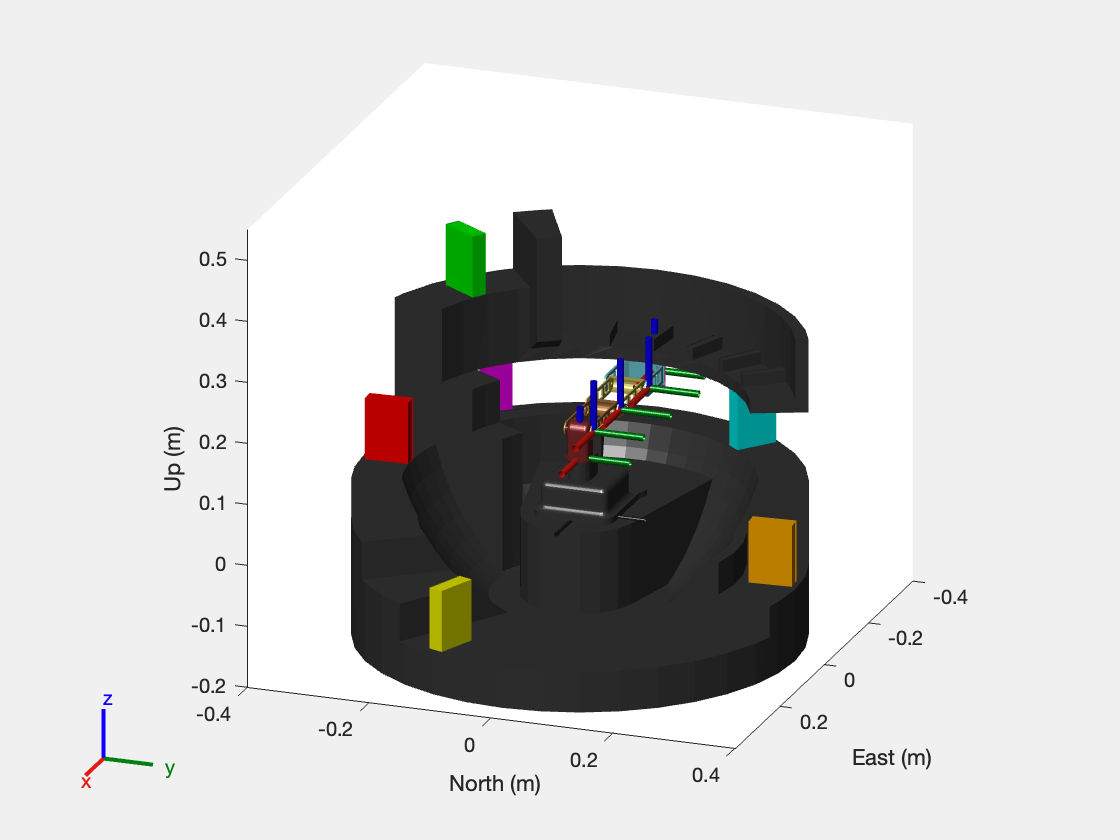

[ax,plotFrames] = show3D(scenario,Collisions="off");
view(ax, 110, 20);
axis equal

axis(ax, 'equal'); 
xlim(ax, [-0.4 0.4] ); 
ylim(ax, [-0.4 0.4] ); 
zlim(ax, [-0.2 0.55] );

light
drawnow;
hold on;

## 1. Forward Kinematics

### 1.1 Approach Overview

In order to calculate the forward kinematics of our 4DOF robot arm, we followed a step-by-step process using the Denavit-Hartenberg (D-H) convention. The process is as follows:

**Started with the robot schematic**

- The Robot Dimensions document was used for the key measurements needed.

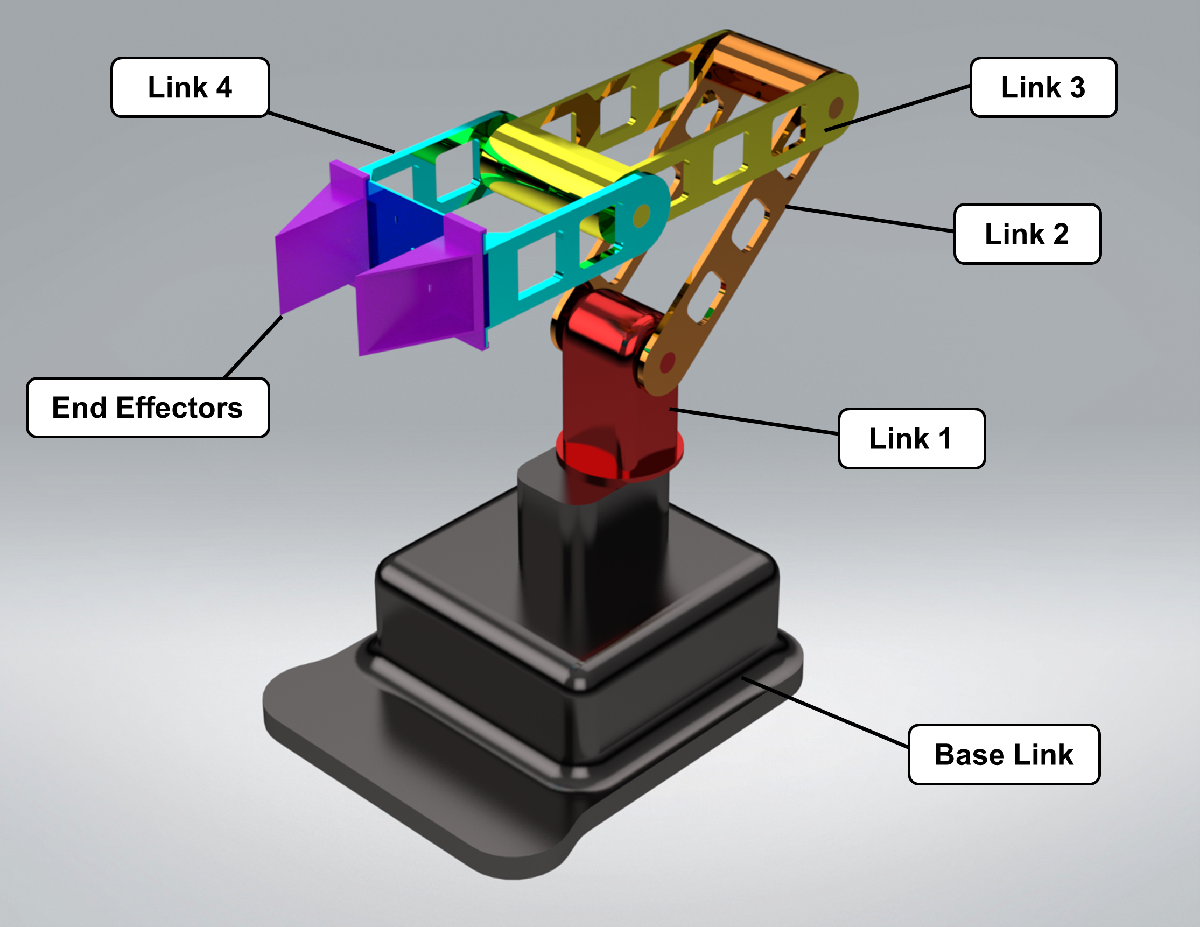

**Assigned coordinate frames to each joint**

- Using the D-H method, we added coordinate frames to every joint in a systematic way. This let us define the four main D-H parameters:

- θ (joint angle)

- d (link offset)

- a (link length)

- α (link twist)

**Built the D-H table**

- Once the frames were set, we pulled all the parameters together into a D-H table. This table maps out how each link connects to the next.

### 1.2 Labelled Denavit-Hartenberg Frame Diagram

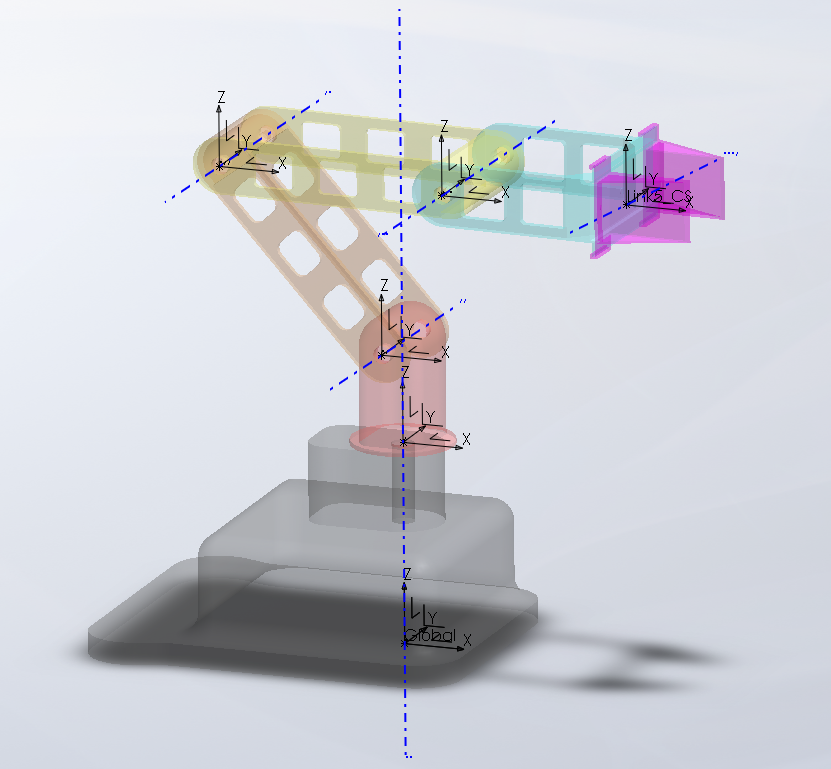

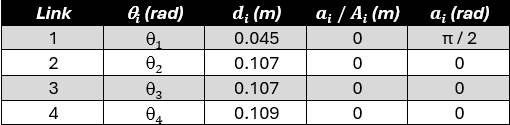

### 1.3 Specify D-H Parameters and Produce a Table

To model the kinematic structure of our 4DOF robot arm, we used the Denavit-Hartenberg (D-H) convention to define the relative transformations between adjacent joints. This approach ensures a structured representation of the robot’s geometry and joint orientations. All parameters were obtained from the schematic in Robot Dimensions.pdf and verified against the robot model imported from the URDF.

We used the standard D-H convention, where:

- θ_i is the joint variable (rotation about Z-axis for revolute joints),

- d_i is the offset along Z_i,

- a_i is the length along X_i,

- α_i is the twist between Z_i and Z_i+1 around X_i.


$$\textrm{dhparams}\;\textrm{in}\;\textrm{Lecture}\;\;\;\;\;\;=\left\lbrack \;\;\;\;\;\theta {\;}_{i\;} \;\;\;\;\;|\;\;d_{i\;} \;\;\;\;\;\;|\;\;\;\;A_{i\;} /a_{i\;} \;\;\;\;|\;\;\;\;\alpha_{i\;} \;\;\;\right\rbrack$$



$$\textrm{dhparams}\;\textrm{in}\;\textrm{MATLAB}\;=\left\lbrack {\;\;A}_{i\;} /a_{i\;} \;\;\;|\;\;\;\;\alpha_{i\;} \;\;\;\;\;\;|\;\;\;\;d_{i\;} \;\;\;\;|\;\;\;\;\theta {\;}_{i\;} \;\;\right\rbrack$$


dhparams = [ 0       pi/2    0.045   0;
             0       0       0.107   0;
             0       0       0.107   0;
             0       0       0.109   0 ];

% Show table in Live Script
disp('D-H Parameters:');

D-H Parameters:


disp(dhparams);

         0    1.5708    0.0450         0
         0         0    0.1070         0
         0         0    0.1070         0
         0         0    0.1090         0



**Explanation of Frame Assignment and D-H Choices**

We carefully followed the D-H convention when assigning frames. Starting from the base, the Z-axes were aligned with the axes of rotation for each joint. The first frame required a twist of **π/2 radians** to align the X-axis properly with the shoulder joint plane. Each subsequent frame was placed at the intersection of adjacent joint axes or along the link offset, based on physical dimensions derived from the CAD model and URDF.

All link lengths and offsets were measured in millimetres and converted to metres. For example:

- The **0.090 m** offset in Link 1 corresponds to the vertical height from the base to the shoulder joint.

- The following offsets (0.045, 0.072, 0.043) represent vertical separations between joints, consistent with the robot’s planar architecture.

## 2. Build Robot in MATLAB Robotics Toolbox

### **2.1 Approach Explanation and Notes**

We chose to design our robot in SolidWorks for greater control over the mechanical layout and visual fidelity. Once the mechanical structure was finalised, we exported the model as a URDF file. This allowed us to directly import the robot into MATLAB without needing to manually define each link using D-H parameters. This approach also enabled us to focus more on trajectory generation and animation within the simulation environment.

We then added a collision sphere to the tool centre point (TCP) of the end-effector using both `addCollision` and `addVisual`. This 5 mm sphere is used to detect contact with books in the interactive environment. Visual geometry was retained from the URDF, though additional visual primitives could have been added if needed.

The robot was displayed using the `show()` function in its home configuration. Any required changes to this configuration were made via the `homeConfiguration` array, which stores the default joint angles. We verified that the imported robot model had all links and joints properly loaded using `showdetails(robotRBT)`.

% Our robot was created in SolidWorks and exported as a URDF

### 2.2 Setup Variables

% Key Co-ordinates
zero_congif = [0,0,0,0];
homeconfig = [180, -90, 90, -90]    % Display output (key info)

homeconfig =    180   -90    90   -90


centre = [-0.00029, 0.00037];
mid_point = [90	-90	90	90];

% Link Lengths
L1 = 0.135;   
L2 = 0.107;  
L3 = 0.107; 
L4 = 0.109; 

% Number of interpolation steps
numSteps = 10;
numSteps_mid = 1;
numSteps_straight = 20;

% Scale for the mid-points for each book position
num_mid_points = 10;
radius_scale = 0.6;

% Make the red_shelf co-ordinate slightly more to the right
red_book_turn_offset = 3.5;

%Offset for shelf height and collecting books in a straight line
height_shelf_offset = 0.01;
book_straight_collect_offset = 0.027;

%% Setup offset for books which aren't picked up straight
%% This was done in the setup stage to allow for easy testing and changing of values
red_pos_orange_offset = 0.07;
red_pos_orange_offset_radius = 0.03;
red_pos_green_offset = -0.13;
red_pos_yellow_offset = 0.14;
red_pos_yellow_offset_radius = 0;

### 2.3 Setup Translation Matrixes

% Define baseline translation
translation = trvec2tform([-0.042, -0.013, -0.016]);

% Define 90° rotation around X-axis
rotationX = axang2tform([1 0 0 pi/2]);

% Define 90° counterclockwise rotation around Z-axis (from above)
rotationZ = axang2tform([0 0 1 pi/2]);

% Combine: First rotate X, then Z, then translate
customTransform = translation * rotationZ * rotationX; 


%%% Setup the angles of theta
%%% This was used to help orientate the books that aren't picked up horizontally
theta_o = pi/8;
theta_y = 0.55;
theta_g = -0.7;


%%% Calculate each of the rotational matrices based on theta
rot_orange = [1, 0,  0, 0;
              0, cos(theta_o), -sin(theta_o), 0;
              0, sin(theta_o), cos(theta_o), 0;
              0, 0, 0, 1];

rot_yellow = [1, 0,  0, 0;
              0, cos(theta_y), -sin(theta_y), 0;
              0, sin(theta_y), cos(theta_y), 0;
              0, 0, 0, 1];

rot_green = [1, 0,  0, 0;
              0, cos(theta_g), -sin(theta_g), 0;
              0, sin(theta_g), cos(theta_g), 0;
              0, 0, 0, 1];


%%% Create another transformation matrix for the books that aren't picked up straight
translation_g = trvec2tform([-0.055, -0.014, -0.02]);
translation_y = trvec2tform([-0.08, -0.014, -0.031]);

customTransform_g = translation_g * rotationZ * rotationX; 
customTransform_y = translation_y * rotationZ * rotationX; 

%%%Find the Transform Matrix for each book incorperating the rotational changes
%%%The ensures the books attatch at the right orientation and positions to the end effector for book 3,4,5

orange_book_trans = customTransform*rot_orange;
yellow_book_trans = customTransform_y*rot_yellow;
green_book_trans = customTransform_g*rot_green;

### 2.4 Adding Robot Collisions 

% We add a collision sphere to the TCP (end-effector) for detecting contact.
showdetails(robotRBT)

--------------------
Robot: (6 bodies)

 Idx             Body Name      Joint Name      Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------      ----------      ----------             ----------------   ----------------
   1                Link_1          Joint1        revolute                 Base_Link(0)   Link_2(2)  
   2                Link_2          Joint2        revolute                    Link_1(1)   Link_3(3)  
   3                Link_3          Joint3        revolute                    Link_2(2)   Link_4(4)  
   4                Link_4          Joint4        revolute                    Link_3(3)   End_Effector_1(5)  End_Effector_2(6)  
   5        End_Effector_1        Joint5_1       prismatic                    Link_4(4)   
   6        End_Effector_2        Joint5_2       prismatic                    Link_4(4)   
--------------------


home = homeConfiguration(robotRBT);

% ax = show(robotRBT, "Frames","off", "Collisions","off"); % Check robot loaded correctly

% Add collison to the end effector of your robot
addCollision(robotRBT.Bodies{end},"sphere",0.005, trvec2tform([0,0,0])) % add new collision
addVisual(robotRBT.Bodies{end},"sphere",0.005, trvec2tform([0,0,0]))

isColliding = checkCollision(robotRBT, homeConfiguration(robotRBT), IgnoreSelfCollision="on");

% Possibly useful functions: 
clearCollision(robotRBT.Bodies{1,4})


#### Fully built robot in its home configuration

 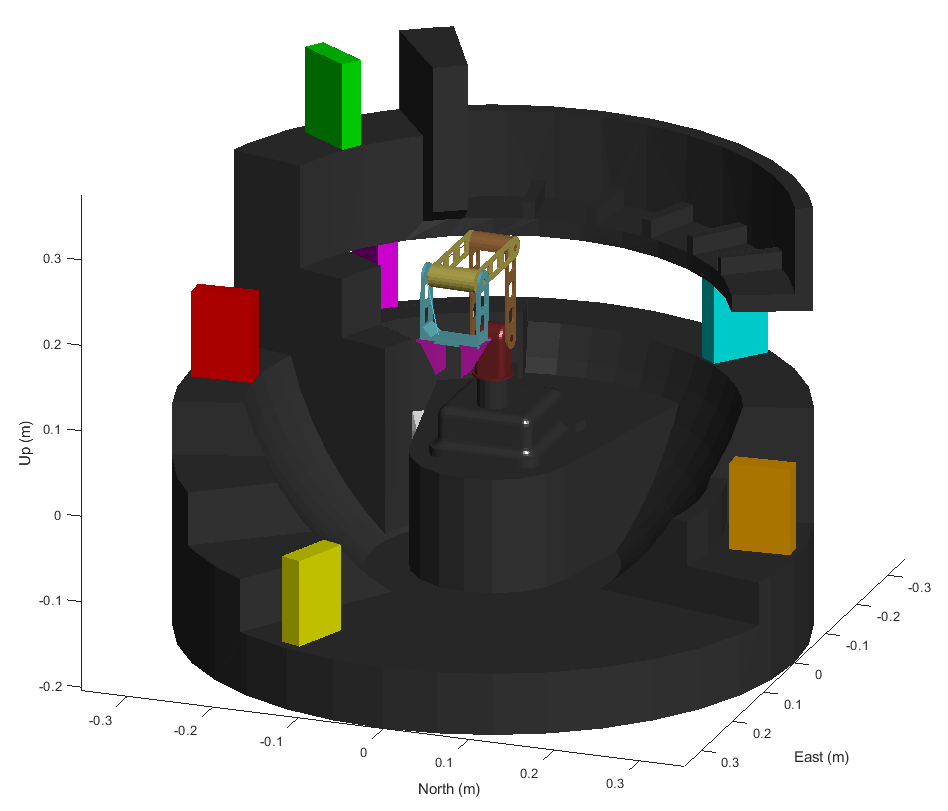

While exporting the model from SolidWorks to URDF we ran into a few obstacles. To improve clarity, we manually edited the URDF to give each link a distinctive RGB colour, making joints and links easy to tell apart. For collision-checking we created a second URDF that contained only bounding (collision) boxes, then merged it with the main Robot_URDF. These added collision bodies proved invaluable when animating the trajectory, helping us detect and minimise potential clashes.

## 3. Inverse Kinematics

Starting in the home configuration, solve for the arm reaching the point where the Book_1 frame lies.

### 3.1 Explain your Approach 

To solve the inverse kinematics (IK) for our custom 4DOF robot, we used a geometric (analytical) method, with the following key steps and assumptions:

**Robot Structure**: A 4DOF planar robot with three revolute joints for positioning and one for orientation. The end effector is a prismatic joint, used to open and close the end effector when reaching the books - to create an accurate motion/animation of picking and dropping off the objects.

**Joint Calculation**:

- **θ₁**: Computed using `atan2(y, x)` for base rotation.

- **θ₂ & θ₃**: Solved using the cosine rule and triangle geometry from the wrist position.

- **θ₄**: Calculated to keep the end-effector horizontal: `θ₄ = -(θ₂ + θ₃)`.

**Wrist Offset**: We accounted for the physical offset of the end-effector by subtracting its length before solving the geometry.

**Assumptions**:

- The robot operates in a known, static environment.

- IK targets are reachable and not obstructed.

- The end-effector orientation is prismatic for book grasping and placing.

**Changes in algorithm for certain books**:

- Book 2 sat behind an obstructing shelf and was vertically boxed in, so a straight pull-out was impossible. The arm therefore rotated about its base joint to sidestep the obstacle, drew the book horizontally toward the library’s centre, and only then lifted it up to its final shelf location.

- For books 3, 4 and 5 the arm could not reach with the end-effector held level, so the books could not be laid flat straight away. Our workaround was to grasp each book at a chosen tilt, detatch it on an intermediate shelf while the robot re-orientated, and then pick it up again with the end-effector now horizontal before placing it flat in its final position.

### 3.2 Solve Analytically

#### 3.2.1 Calculate the book co-ordinates

% Define the books data (initial base positions and updated colors)
book_1 = struct('name', 'Book_1', 'position', [0.014018 -0.30839 0.13881], 'bookSize', [0.025 0.1 0.07], 'Color', [1 0 0]);   % Red
book_2 = struct('name', 'Book_2', 'position', [-0.019668 0.30852 -0.002738], 'bookSize', [0.025 0.1 0.07], 'Color', [1 0 1]);   % Pink
book_3 = struct('name', 'Book_3', 'position', [0.28417 -0.10873 -0.047996], 'bookSize', [0.025 0.1 0.07], 'Color', [0 1 0]);   % Green
book_4 = struct('name', 'Book_4', 'position', [-0.16721 -0.24817 0.36203], 'bookSize', [0.025 0.1 0.07], 'Color', [1 0.647 0]); % Orange
book_5 = struct('name', 'Book_5', 'position', [-0.24541 0.19397 0.13758], 'bookSize', [0.025 0.1 0.07], 'Color', [1 1 0]);   % Yellow
book_6 = struct('name', 'Book_6', 'position', [-0.22945 -0.22148 0.13758], 'bookSize', [0.025 0.1 0.07], 'Color', [0 0 1]);    % Blue

% Put the books in a cell array
books = {book_1, book_6, book_4, book_2, book_3, book_5};


% Initialize a matrix to store the coordinates
coordinates = zeros(length(books), 3);

%Loop through and get the book co-ordinates in and store them in a matrix called bookPositions
for i = 1:length(books)
    coordinates(i, :) = books{i}.position; % Get the position of each book and store it in the matrix
end

% Display the coordinates matrix
disp(coordinates);

    0.0140   -0.3084    0.1388
   -0.2294   -0.2215    0.1376
   -0.1672   -0.2482    0.3620
   -0.0197    0.3085   -0.0027
    0.2842   -0.1087   -0.0480
   -0.2454    0.1940    0.1376



bookPositions = coordinates;

#### 3.2.2 Calculate Book Final Cords

% Create a matrix that holds the x,y,z values for the shelf co-ordinates (where to place the books)
shelf_coords = [ -0.247203  ,  -0.0888485   ,  0.305  ;
                 -0.26      ,  -0.015964705 ,  0.305  ;
                 -0.256188  ,   0.0580598   ,  0.305  ;  
                 -0.230686  ,   0.122       ,  0.305  ;
                 -0.184746  ,   0.186741    ,  0.305  ;
                 -0.125306  ,   0.229985    ,  0.305   ]

shelf_coords =    -0.2472   -0.0888    0.3050
   -0.2600   -0.0160    0.3050
   -0.2562    0.0581    0.3050
   -0.2307    0.1220    0.3050
   -0.1847    0.1867    0.3050
   -0.1253    0.2300    0.3050


#### 3.2.3 Calculate Mid-Points for Books

%% Setup between points for the robot to move to
%% These were created to ensure the robot does not collide with anything by making it move through extra waypoints
%% There are 4 mid-points used, but a 6th row is included to allow for additional points to be added easily if needed

between_point = [ 0, -0.1, 0.35;
                 -0.05, 0, 0.35 ;
                 0.15, 0.15, 0.13758  ;  
                 0.05, 0.15, 0.40  ;
                 -0.05  ,   0    ,  0.305  ;
                 -0.05  ,  0    ,  0.305   ]

between_point =          0   -0.1000    0.3500
   -0.0500         0    0.3500
    0.1500    0.1500    0.1376
    0.0500    0.1500    0.4000
   -0.0500         0    0.3050
   -0.0500         0    0.3050




%% These in between points are specific angles of the robot and therefore seperate from the others
between_point_angle = mid_point;
between_point_angle(1, 1) = -180;
between_point_angle(1, 4) = 0;

between_point_angle(2, :) = [-56.1146055033277, -80, 0, 0];
between_point_angle(3, :) = homeconfig;
between_point_angle(3, 4) = 0;

## 4. Trajectory Generation

Generate a trajectory for your End-Effector to follow such that the robots Tool Centre Point presses each of the books in the correct order. (20%)

### 4.1 Explain your approach

Our Trajectory Generation followed 3 specific options:

**a) Point-to-Point Movement**

In this process, the points to move to, are laid out in a matrix altogether e.g. when moving the robot arm fowards to pick up a book. The matrix contains all of the angles needed for each point and the robot is simply set to move to that configuration. This is done by using the **animateRobotTrajectory **function and setting the number of steps to 1. This immediatley 'snaps' the robot to the next position which done in succession, moves the robot.

The only deviation from this, is when rotating the robot's base after picking up the purple book. In this case, multiple angles are not calculated as the only value that needs changing is the base's rotation. To solve this, a for loop continously adds to base rotation's value and uses the **animateRobotTrajectory** function with 1 step to make it 'snap' between positions.

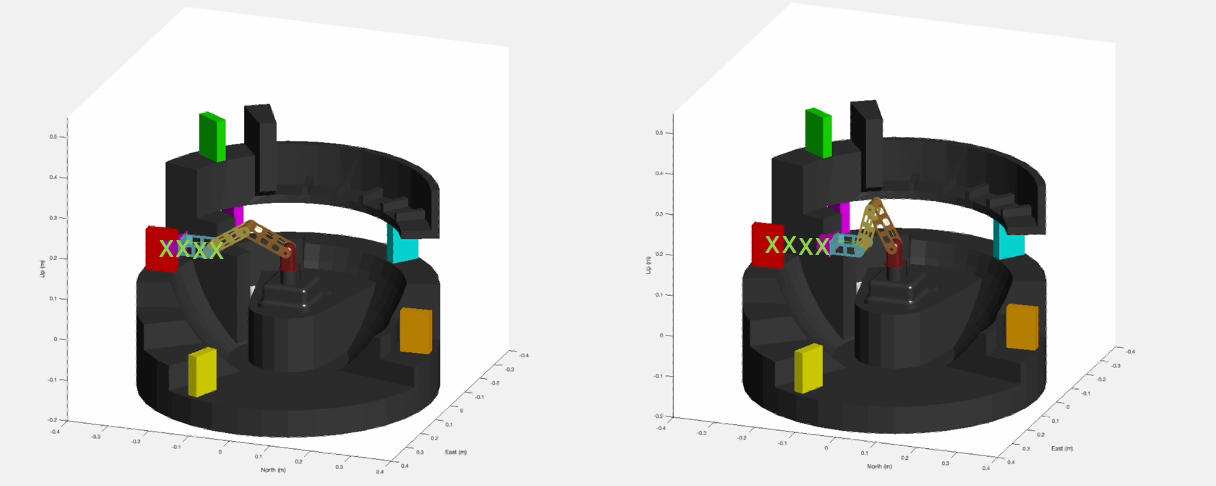

**b) Fluid Cosine Movement**

For larger more complex movements, a fluid cosine function was used. This uses an input of two positions (the start and end position) and uses the **animateRobotTrajectory **function with a larger number of steps. By doing so, the robot plots a number of points between these two points, for which the robot can travel between. 

The difference between the starting and ending joint angles (`delta`) is calculated, with the `wrapToPi` function ensuring that this difference represents the shortest path for rotation (avoiding unnecessary long rotations). The function then defines a time parameter `t` that progresses from 0 to 1 over `numSteps` steps, using a cosine ease-in-out function (`s`) to create smooth acceleration and deceleration during the movement. The joint trajectory (`q_traj`) is interpolated by adding the scaled angular differences to the starting joint angles. Finally, the robot's joint angles are updated step by step in a loop, with each configuration visualised in a 3D plot.

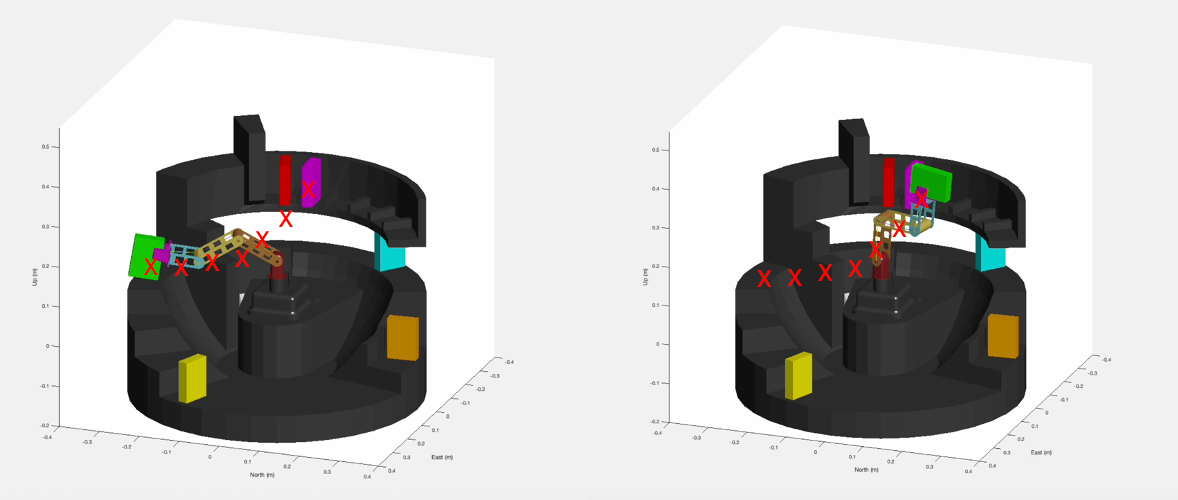

**c) Open/Close End Effector**

The **animateRobotTrajectory **has two values as it's last inputs which are set to 0 or 1

The penultimate input is relating to the start position (of a movement)

The last input is relating to the end position (of a movement)

For each case the values represent:

0 --> End effector is shut

1 --> End effector is open

Hence, to open and close the end effector while staying still, you would input the same robot 'positions' but change the last values of the input to be:

(....., 0, 1) ---> Open end effector

(....., 1, 0) ---> Close end effector

And if you are moving to a new position, you would input the values as:

(....., 0, 0) ---> Keep Closed

(....., 1, 1) ---> Keep Open

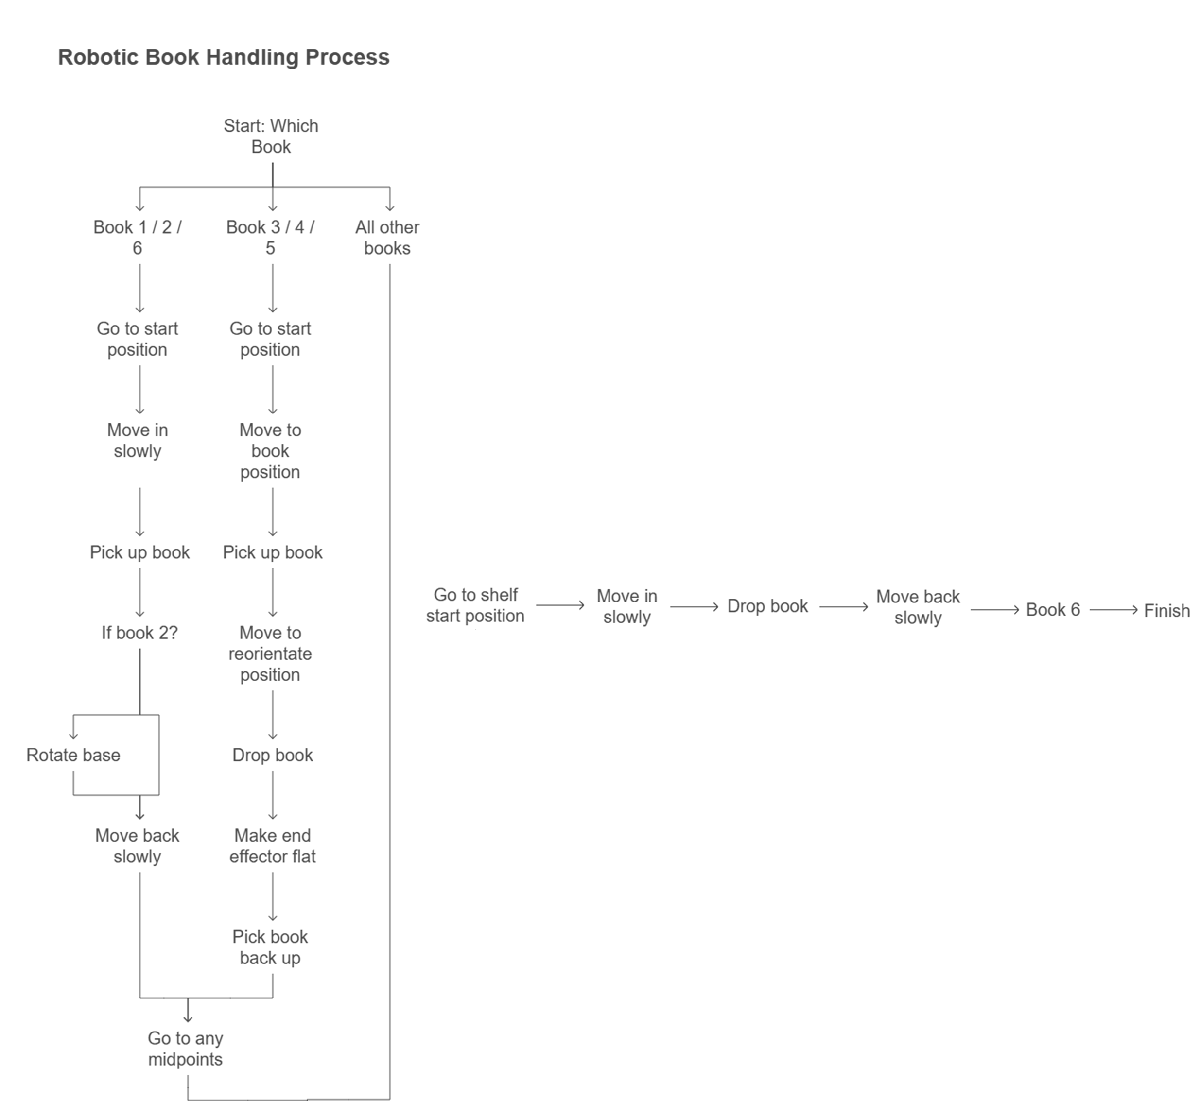

### 4.2 Generate Theta Matrix

Matrix of theta values containing your robots joint angle data to be plotted in your animation.

#### 4.2.1 Book Positions

**1. Calculate Mid Positions for each of the points for All Books**

% Our trajectory calculations use the distance from the centre of the robot and the height of the book
% The function 'calculateResults' calcaulate these values and stores them

results = calculateResults(bookPositions, L1);

Results Matrix (Radius, Original Z):
    0.3087    0.0038
    0.3189    0.0026
    0.2992    0.2270
    0.3091   -0.1377
    0.3043   -0.1830
    0.3128    0.0026




% Fix a slight height issue for books with straight end collection method with an offset
% This is done by decreasing the height value calculated from 'calculateResults'
results(1, 2) = results(1, 2) - book_straight_collect_offset;
results(2, 2) = results(2, 2) - book_straight_collect_offset;
results(6, 2) = results(6, 2) - book_straight_collect_offset;

%Loop through and make a matrix full of each books individual points
for i = 1:6
    eval(['results_book_' num2str(i) ' = results(' num2str(i) ', :);']);
end

% Create 10 points within each matrix which are at smaller radius values
% This is used to allow the robot to slowly move fowards and pick the books up
% The nested loop does this for all 6 book positions

for i = 1:6
    % Define the book name dynamically
    results_book_name = ['results_book_' num2str(i)];
    results_book_10_points = zeros(num_mid_points, 2);  % Initialize the result array for each book

    % Loop through the mid-points and calculate for each book
    for j = 1:num_mid_points
        difference = (eval([results_book_name '(1, 1)']) - (radius_scale * eval([results_book_name '(1, 1)']))) / num_mid_points; 
        results_book_10_points(j, 1) = eval([results_book_name '(1, 1)']) - ((1 + num_mid_points - j) * difference);

        %Add a slighty increase in height for each position due to shelf clipping
        results_book_10_points(j, 2) = eval([results_book_name '(1, 2)']) ;
    end

    % Assign the calculated points to a dynamically named variable
    assignin('base', [results_book_name '_10_points'], results_book_10_points);
end

**2. Find Theta 1**

% This create a matrix to store the final robot limb angles for each book called final_angles_(book_number)
% For books 3,4 & 5, the robot can't reach moving fowards slowly, hence only 1 row is made

% Loop to create matrices with different sizes for book numbers
for i = 1:6
    if i == 3 || i == 4 || i == 5
        % For book numbers 3, 4, and 5, create a 1x4 matrix
        eval(['final_angles_' num2str(i) ' = zeros(1, 4);']);
    else
        % For book numbers 1, 2, and 6, create a 10x4 matrix
        eval(['final_angles_' num2str(i) ' = zeros(10, 4);']);
    end
end

% Find Theta 1 for book cords using the 'calculateTheta1' function and store in final_angles for each book
% This relates to the rotation of the base of the robot
final_angles_1(:, 1) = calculateTheta1(bookPositions(1, :), centre)

final_angles_1 =   -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0


final_angles_2(:, 1) = calculateTheta1(bookPositions(2, :), centre)

final_angles_2 =   -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0


final_angles_3(:, 1) = calculateTheta1(bookPositions(3, :), centre)

final_angles_3 =   -56.1146         0         0         0


final_angles_4(:, 1) = calculateTheta1(bookPositions(4, :), centre)

final_angles_4 =    86.4017         0         0         0


final_angles_5(:, 1) = calculateTheta1(bookPositions(5, :), centre)

final_angles_5 =  -159.0165         0         0         0


final_angles_6(:, 1) = calculateTheta1(bookPositions(6, :), centre)

final_angles_6 =    38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0


**3. Find Theta 2 & 3 & 4**

% Find Theta 2,3 & 4 for book cords using the 'calculateTheta234' function and store in final_angles for each book
% For books 1,2 & 6, the calculations ensure the end effector is perfectly horizontal

% For books 3,4 & 5, this isn't possible, hence a different function is
% used to calculate the angles, which makes the whole robot straight

final_angles_1(:, 2:4) = calculateTheta234(results_book_1_10_points, L2, L3, L4, 0);
final_angles_2(:, 2:4) = calculateTheta234(results_book_2_10_points, L2, L3, L4, 0);
final_angles_3(:, 2:4) = calculateTheta234_bend(results_book_3, L2, L3, L4);
final_angles_4(:, 2:4) = calculateTheta234_bend(results_book_4, L2, L3, L4);
final_angles_5(:, 2:4) = calculateTheta234_bend(results_book_5, L2, L3, L4);
final_angles_6(:, 2:4) = calculateTheta234(results_book_6_10_points, L2, L3, L4, 0);

#### 4.2.2 Shelf Positions

**1. Calculate Mid Positions for each of the shelf co-ords**

% This repeats the process of for the shelf co-ordinates
% Calculate radius and heights
results = calculateResults(shelf_coords, L1);

Results Matrix (Radius, Original Z):
    0.2627    0.1700
    0.2605    0.1700
    0.2627    0.1700
    0.2610    0.1700
    0.2627    0.1700
    0.2619    0.1700




% Create an empty cell array for the co-ordinates
results_shelf = cell(6, 1);

% Fill with results
for i = 1:6
    results_shelf{i} = results(i, :); 
end

% Loop to create 10 points for each position to slowly put the book onto the shelf
% These are at smaller radius values and higher height values to allow the robot to slowly move down and into the shelf position
% The nested for loop does this for all of the shelf positions
for i = 1:6
    results_shelf_10_points = zeros(num_mid_points, 2); 

    % Loop through the mid-points and calculate for each shelf
    for j = 1:num_mid_points
        % Directly access the results for the current shelf
        difference = (results_shelf{i}(1, 1) - (radius_scale * results_shelf{i}(1, 1))) / num_mid_points; 
        results_shelf_10_points(j, 1) = results_shelf{i}(1, 1) - ((1 + num_mid_points - j) * difference);
        results_shelf_10_points(j, 2) = results_shelf{i}(1, 2) + (( num_mid_points - j) * height_shelf_offset);
    end

    % Assign the calculated points to a dynamically named variable in the base workspace
    assignin('base', ['results_shelf_' num2str(i) '_10_points'], results_shelf_10_points);
end

**2. Find Theta 1**

% Create a blank matrix for each shelf position with 10 rows
for i = 1:6
    eval(['shelf_angles_' num2str(i) ' = zeros(10, 4);']);
end

% Find Theta 1 for shelf cords
shelf_angles_1(:, 1) = calculateTheta1(shelf_coords(1, :), centre) + red_book_turn_offset;
shelf_angles_2(:, 1) = calculateTheta1(shelf_coords(2, :), centre)

shelf_angles_2 =    -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0
   -3.5989         0         0         0


shelf_angles_3(:, 1) = calculateTheta1(shelf_coords(3, :), centre)

shelf_angles_3 =    12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0
   12.7044         0         0         0


shelf_angles_4(:, 1) = calculateTheta1(shelf_coords(4, :), centre)

shelf_angles_4 =    27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0
   27.8303         0         0         0


shelf_angles_5(:, 1) = calculateTheta1(shelf_coords(5, :), centre)

shelf_angles_5 =    45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0
   45.2959         0         0         0


shelf_angles_6(:, 1) = calculateTheta1(shelf_coords(6, :), centre)

shelf_angles_6 =    61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0
   61.4335         0         0         0


**3. Find Theta 2 & 3 & 4**

% Find Theta 2, 3 & 4 for shelf cords
shelf_angles_1(:, 2:4) = calculateTheta234(results_shelf_1_10_points, L2, L3, L4, 0);
shelf_angles_2(:, 2:4) = calculateTheta234(results_shelf_2_10_points, L2, L3, L4, 0);
shelf_angles_3(:, 2:4) = calculateTheta234(results_shelf_3_10_points, L2, L3, L4, 0);
shelf_angles_4(:, 2:4) = calculateTheta234(results_shelf_4_10_points, L2, L3, L4, 0);
shelf_angles_5(:, 2:4) = calculateTheta234(results_shelf_5_10_points, L2, L3, L4, 0);
shelf_angles_6(:, 2:4) = calculateTheta234(results_shelf_6_10_points, L2, L3, L4, 0);


#### 4.2.3 Book Between Positions

% Complete all the calculations again for the mid-positions
% Find the radius and height of the values
results_mid = calculateResults(between_point, L1);

Results Matrix (Radius, Original Z):
    0.1000    0.2150
    0.0500    0.2150
    0.2121    0.0026
    0.1581    0.2650
    0.0500    0.1700
    0.0500    0.1700




%Create a blank matrix
mid_angles = zeros(6, 4);

%Loop through and calculate theta 1
for i = 1 : 4
    mid_angles(i, 1) = calculateTheta1(between_point(i, :), centre);
end

%Loop through and calculate theta 2, 3 & 4
mid_angles(:, 2:4) = calculateTheta234(results_mid, L2, L3, L4, 0);


#### 4.2.4 Book Between Purple

% In order to bring the robot's position back to the centre after picking up the purpple book, 
% 10 points at smaller radius's need to be created

% To keep this simple, a copy of the extending radius values are copied from final_angles_2,
% and then the base radius (angle 1) is changed 

% Create a copy of the mid positions
purp_mid_bring_back = final_angles_2;

%Make the angle equal to -4.07142751139033
%This is the base angle after picking up purple book and rotating round the barrier

purp_mid_bring_back(:, 1) = -4.07142751139033;

#### 4.2.4 Calculate the 'offset' positions for picking the book up at an angle

% When a book is picked up at an angle, some offsets of radius and height
% need to be made when placing the book in the 'red position' for reorienting
% The following is setup for easy testing using the values outlined at the beginning

% Set the red position equal to new values
red_pos_orange(1, 1) = final_angles_1(1,1);
red_pos_green(1, 1) = final_angles_1(1,1);
red_pos_yellow(1, 1) = final_angles_1(1,1);

% Add a radius/height offset for the orange book
red_pos_orange_results = results_book_1_10_points(10, :);
red_pos_orange_results(1, 1) = red_pos_orange_results(1, 1) + red_pos_orange_offset_radius;
red_pos_orange_results(1, 2) = red_pos_orange_results(1, 2) + red_pos_orange_offset;

% Add a radius/height offset for the green book
red_pos_green_results = results_book_1_10_points(10, :);
red_pos_green_results(1, 2) = red_pos_green_results(1, 2) + red_pos_green_offset;

% Add a radius/height offset for the yellow book
red_pos_yellow_results = results_book_1_10_points(10, :);
red_pos_yellow_results(1, 1) = red_pos_yellow_results(1, 1) + red_pos_yellow_offset_radius;
red_pos_yellow_results(1, 2) = red_pos_yellow_results(1, 2) + red_pos_yellow_offset;


%% Calculate the angles for 2,3 & 4
%% The final value input isn't 0 anymore as the end effector isn't straight
%% Instead it inputs the offsets for orientation setup at the beginning
red_pos_orange(:, 2:4) = calculateTheta234(red_pos_orange_results, L2, L3, L4, -theta_o);
red_pos_green(:, 2:4) = calculateTheta234(red_pos_green_results, L2, L3, L4, -theta_g);
red_pos_yellow(:, 2:4) = calculateTheta234(red_pos_yellow_results, L2, L3, L4, -theta_y);

## 5. Create your Animation/Video/Recording

### 5.1 - Book 1

%%%% Book 1 pick up and place down
%%%% Set loop number to 1
k = 1

k = 1

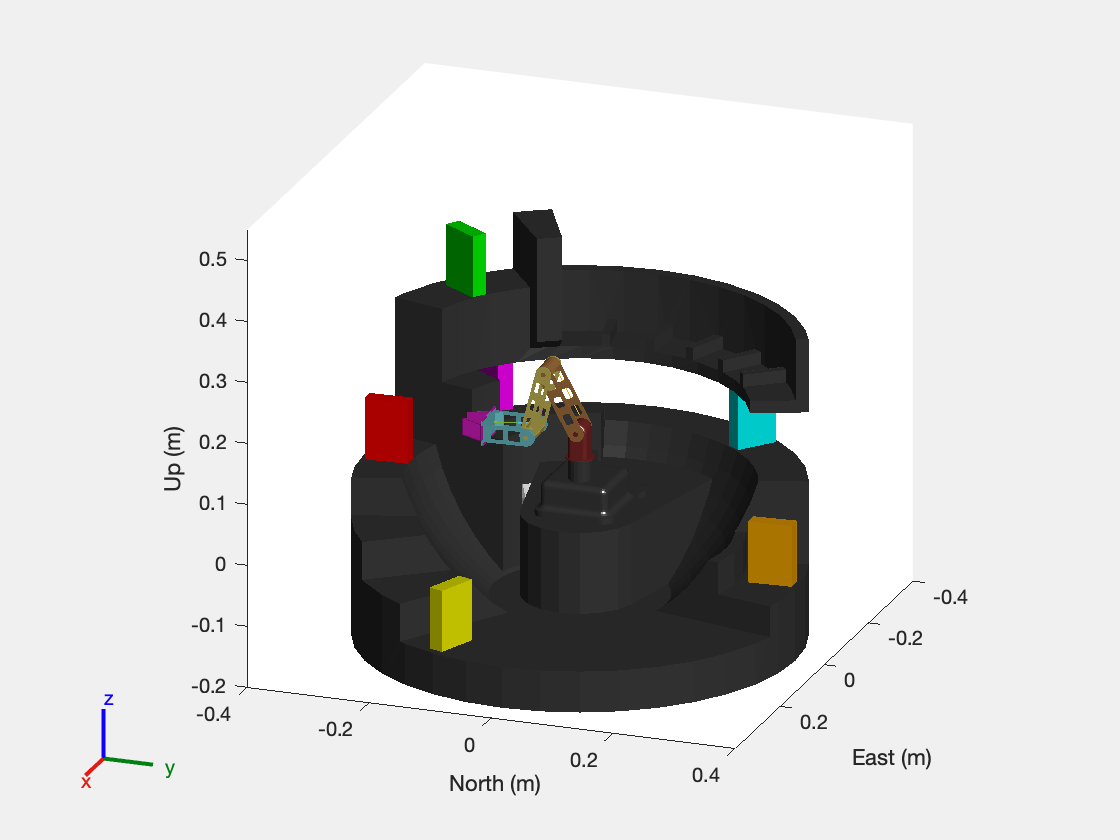


%To make the process easy to repeat, the following code set's the number of points and current angles, relative to the loop number
numPoints = size(eval(['final_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['final_angles_' num2str(k)]);  % final_angles_1, final_angles_2, ..., final_angles_6

%%% Move from the home config to the first position for the red book
animateRobotTrajectory(scenario, Robot, ax, homeconfig, current_angles(1, :), numSteps, 0, 0);

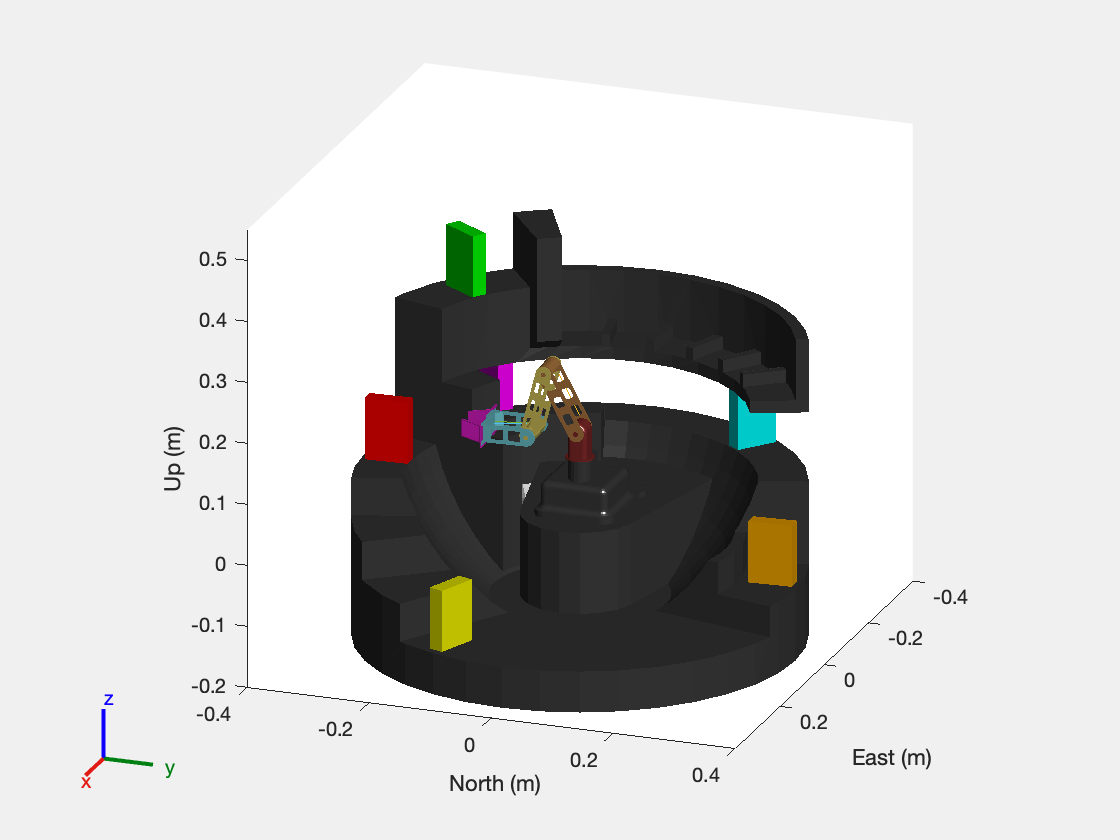


% Open the end effector
animateRobotTrajectory(scenario, Robot, ax, current_angles(1, :), current_angles(1, :), numSteps, 0, 1);

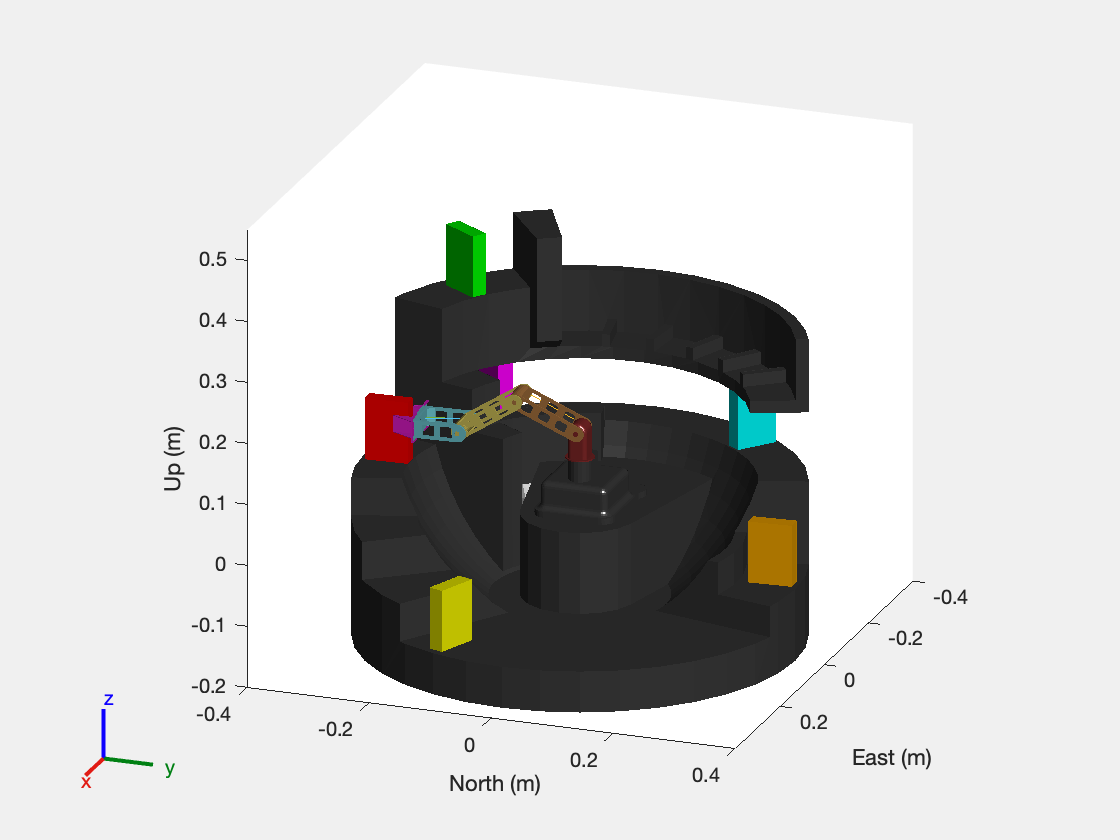


%% Loop through the 10 points mid-points, slowly moving out to the book
for i = 1 : numPoints-1

    %% Set the points for the current row and the row below
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);

    %% Move between the two points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 1, 1);
end

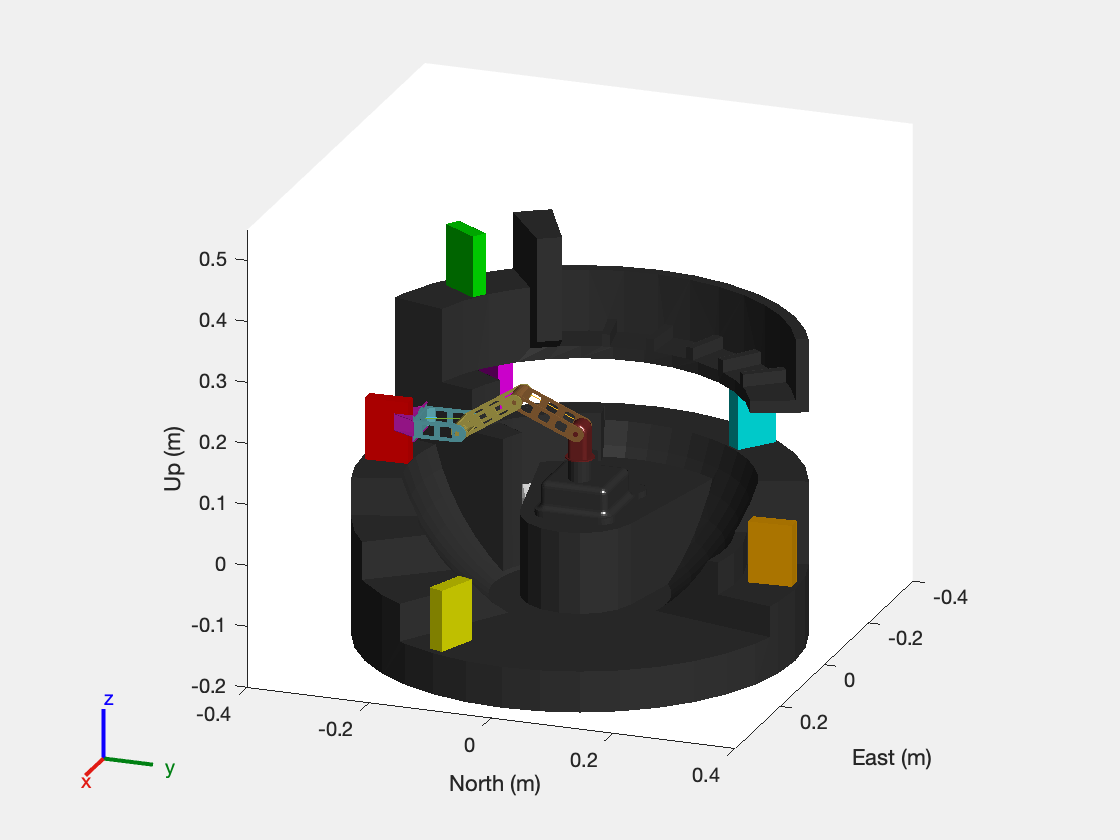


%Close the end effector
animateRobotTrajectory(scenario, Robot, ax, secondPoint, secondPoint, numSteps, 1, 0);


%% Attach the book
attach(Robot, books{1}.name, "End_Effector_1", ...
    'ChildToParentTransform', customTransform);


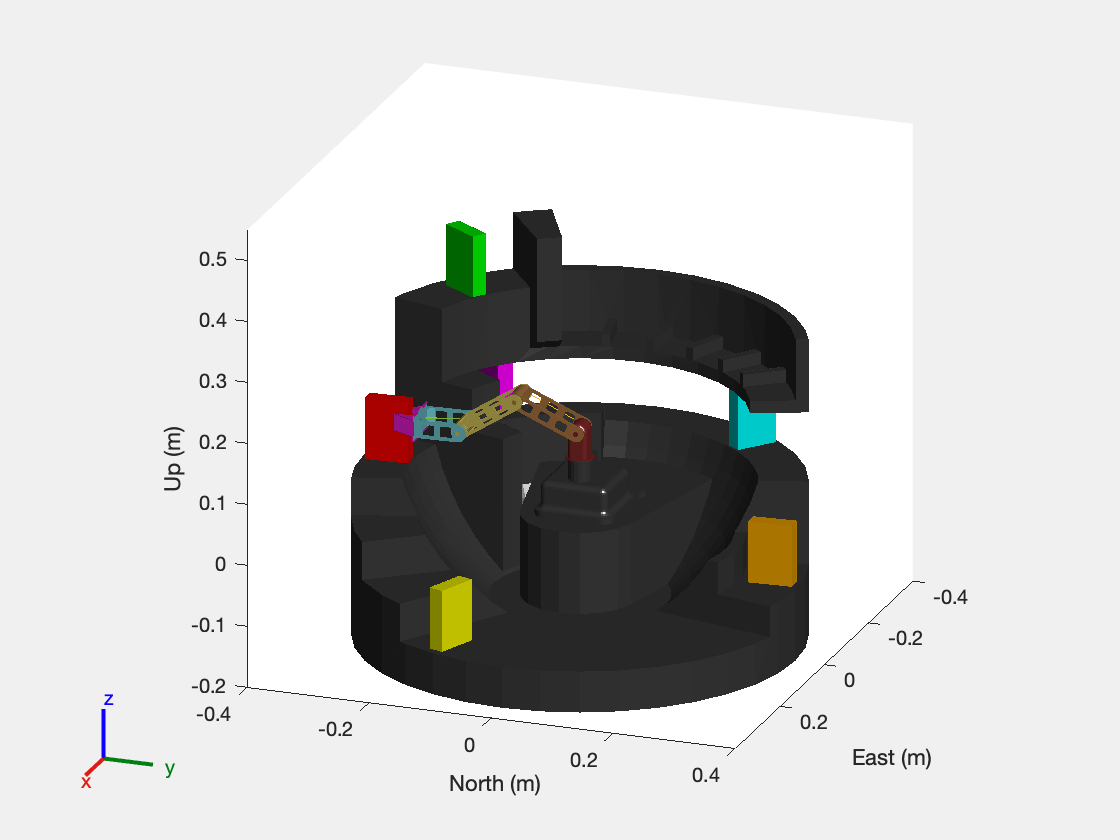

%% Now that you have picked up the book, draw the robot back
%% Move between mid-point to draw the book back
animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 0, 0);

secondPoint =   -92.6532  -30.0235   69.3830   39.3594


secondPoint =   -92.6532  -35.2382   80.2347   44.9965


secondPoint =   -92.6532  -39.8787   89.9780   50.0992


secondPoint =   -92.6532  -44.1106   98.9498   54.8392


secondPoint =   -92.6532  -48.0316  107.3529   59.3213


secondPoint =   -92.6532  -51.7041  115.3207   63.6166


secondPoint =   -92.6532  -55.1697  122.9471   67.7775


secondPoint =   -92.6532  -58.4563  130.3015   71.8452


secondPoint =   -92.6532  -61.5823  137.4372   75.8548


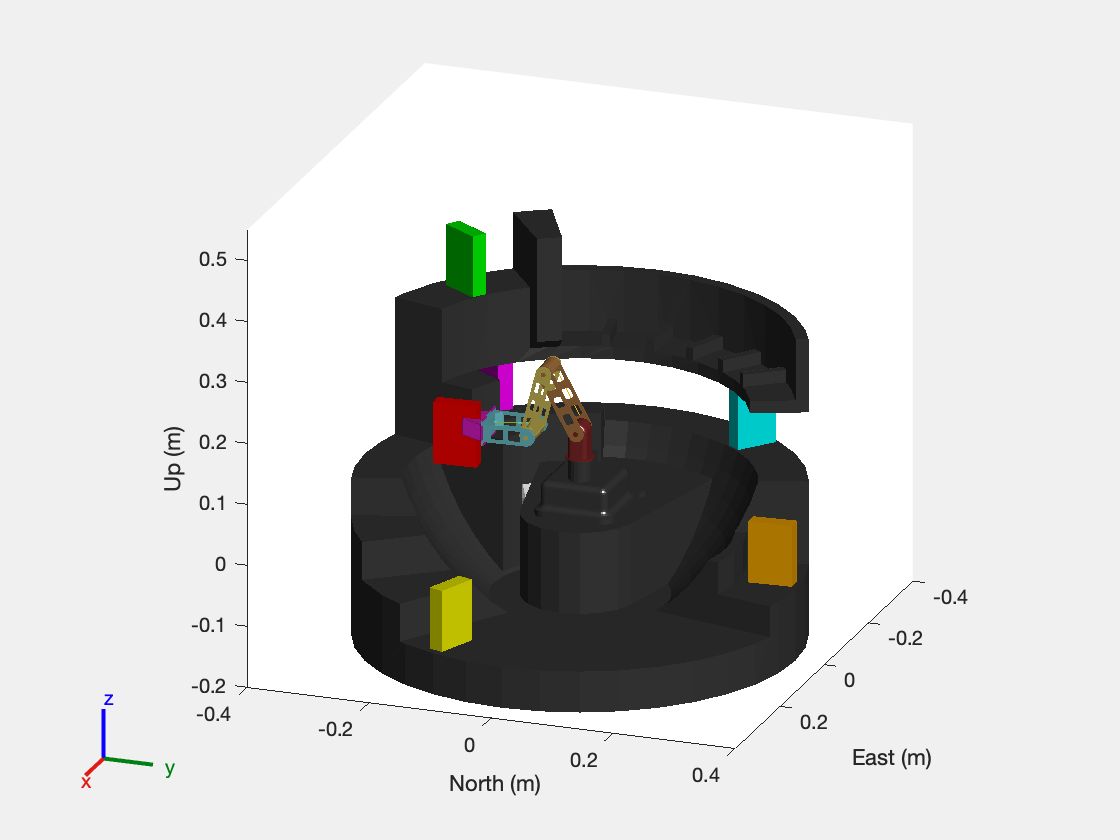


% Loop through all consecutive points in reverse order for the current angles
for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :)

    t = numSteps_mid;


    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, t, 0, 0);

end



% Record the current point to allow for referencing in the next movement function
current_point = secondPoint;


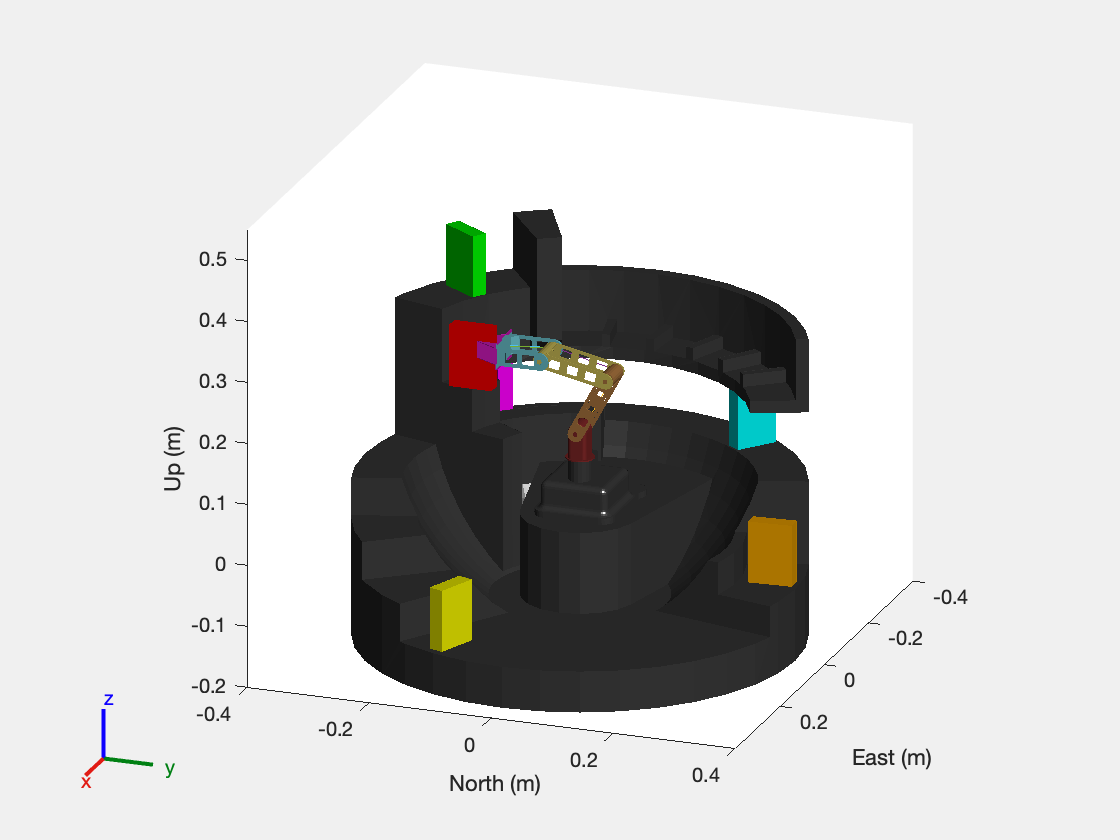

% Now focus on moving towards the shelf
% Set the next angles to be equal to the shelf co-ordinates
numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]); 

%%%% Move between the mid-points to setup placing the book down
animateRobotTrajectory(scenario, Robot, ax, current_point, mid_angles(1, :), numSteps, 0, 0);

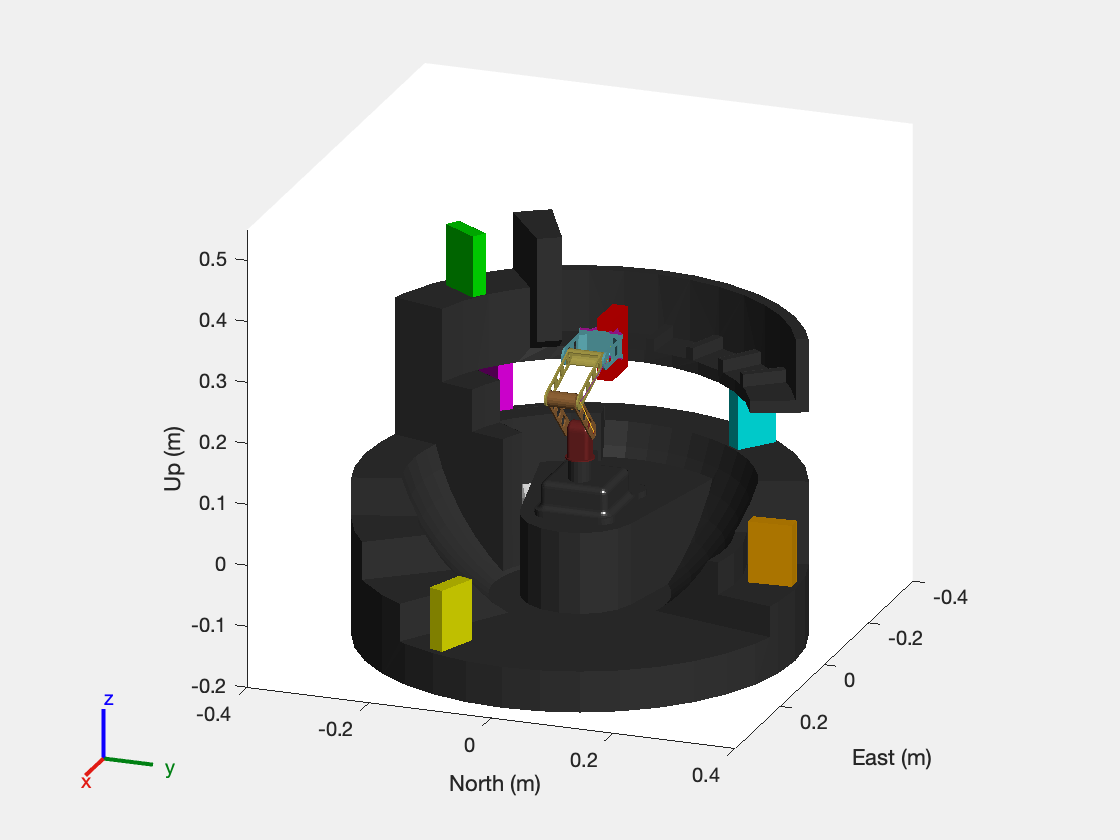

animateRobotTrajectory(scenario, Robot, ax, mid_angles(1, :), mid_angles(2, :), numSteps, 0, 0);

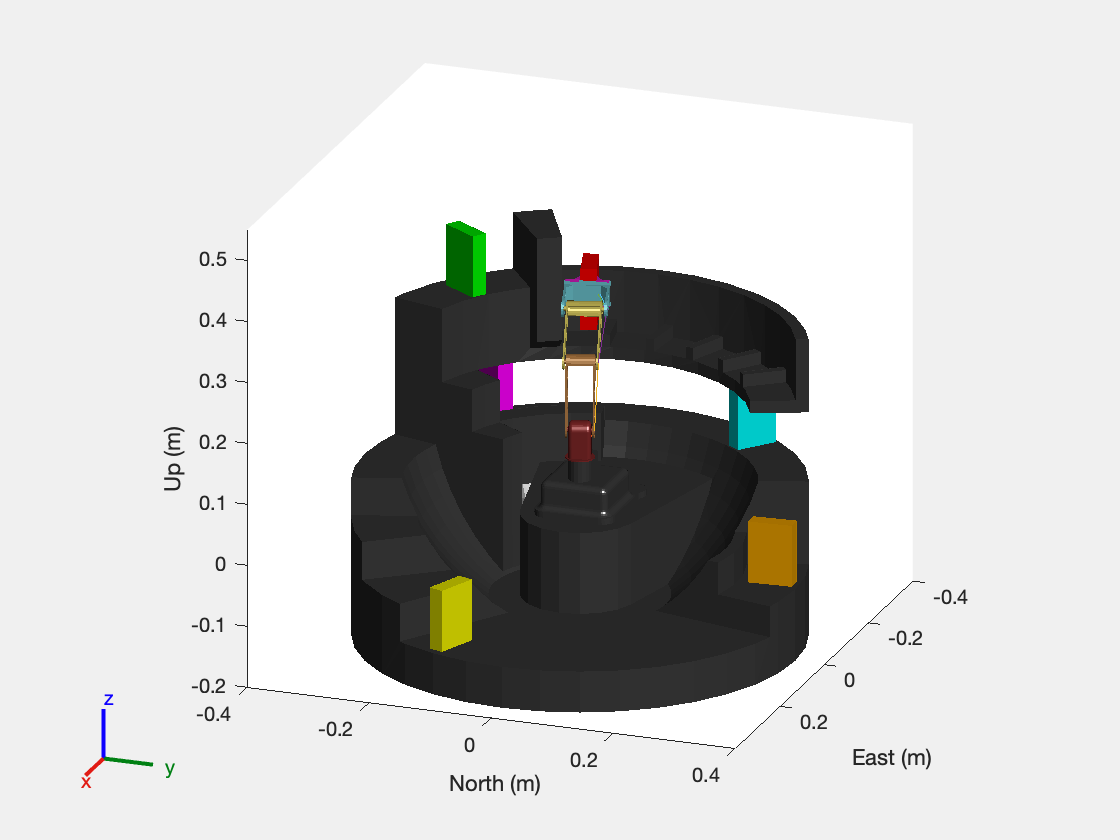

animateRobotTrajectory(scenario, Robot, ax, mid_angles(2, :), current_angles(i, :), numSteps, 0, 0);

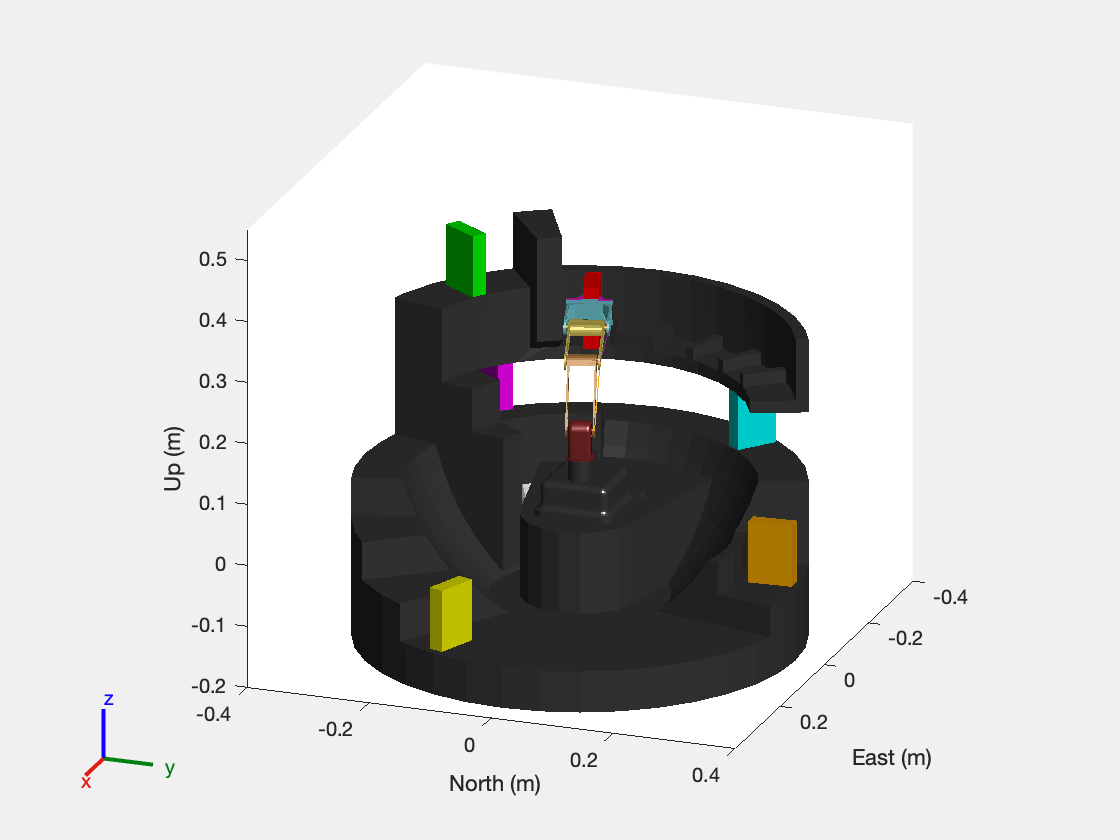



% Go through the shelf mid points to place book down slowly
for i = 1:numPoints - 1

    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 0, 0);
end

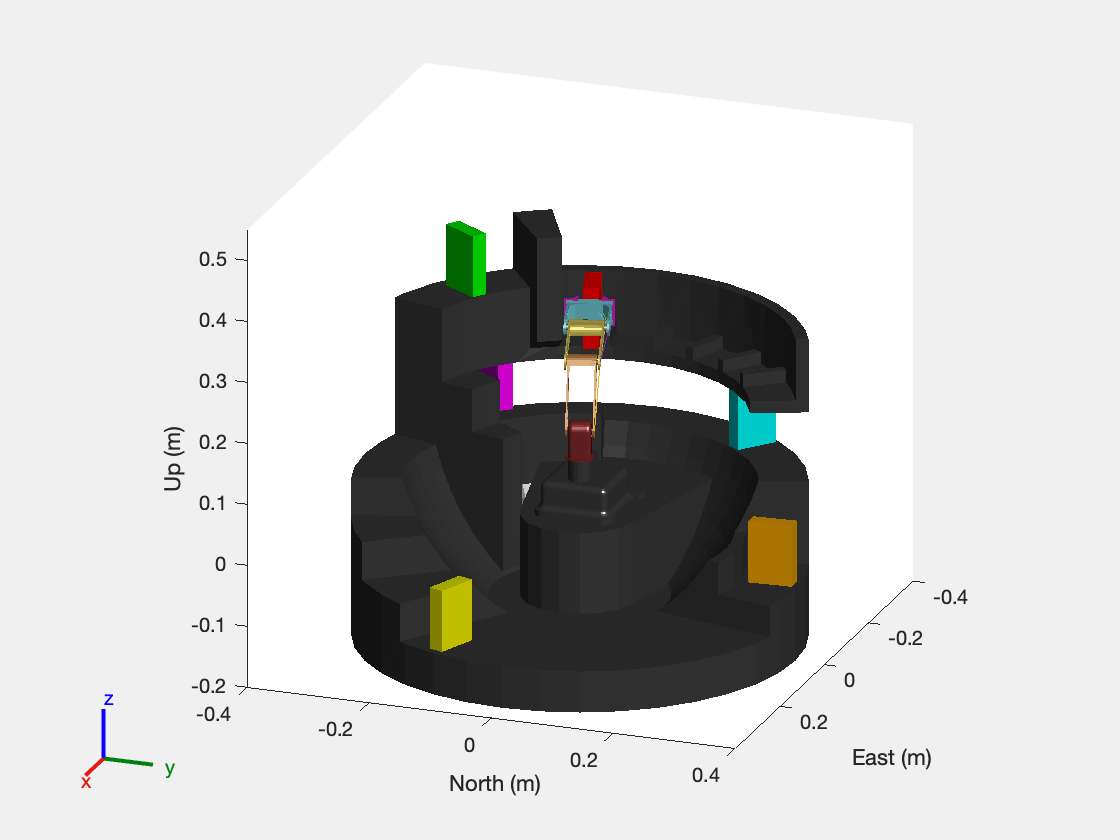


% Detatch the book
detach(Robot);

% Open the end effector
animateRobotTrajectory(scenario, Robot, ax, secondPoint, secondPoint, numSteps, 0, 1)

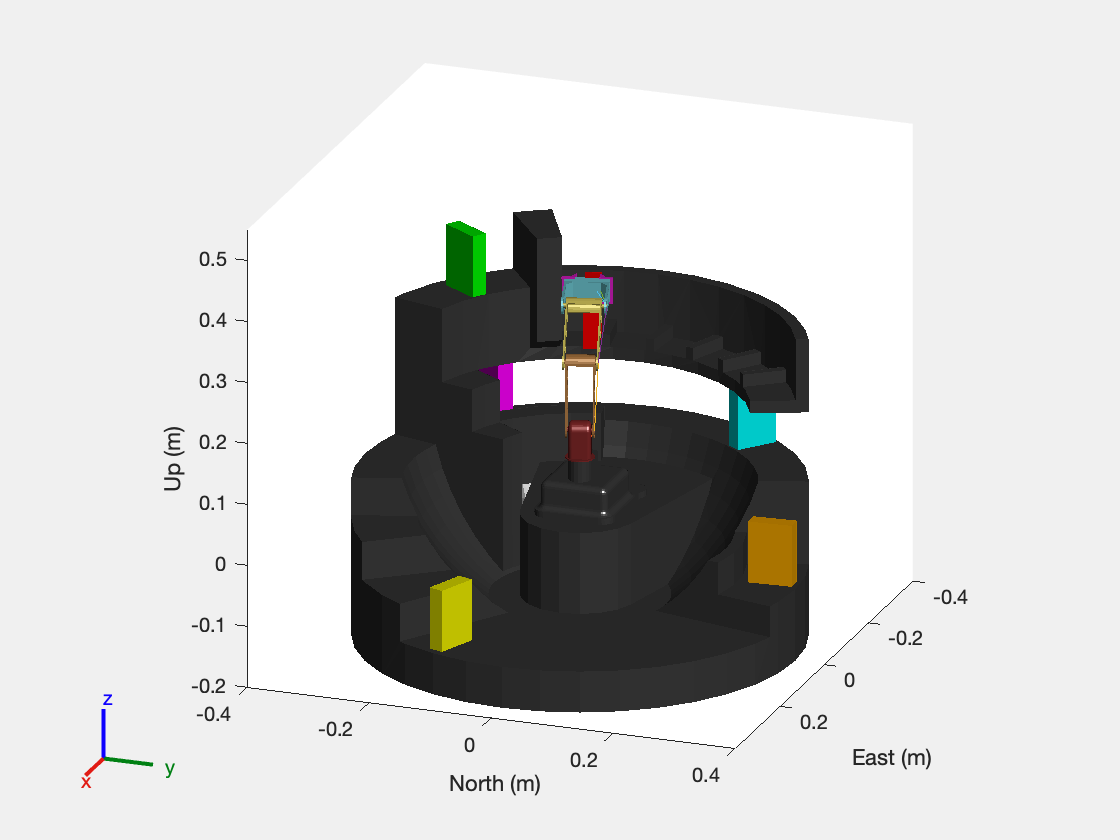


% Move slowly backwards
for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 1, 1);
end

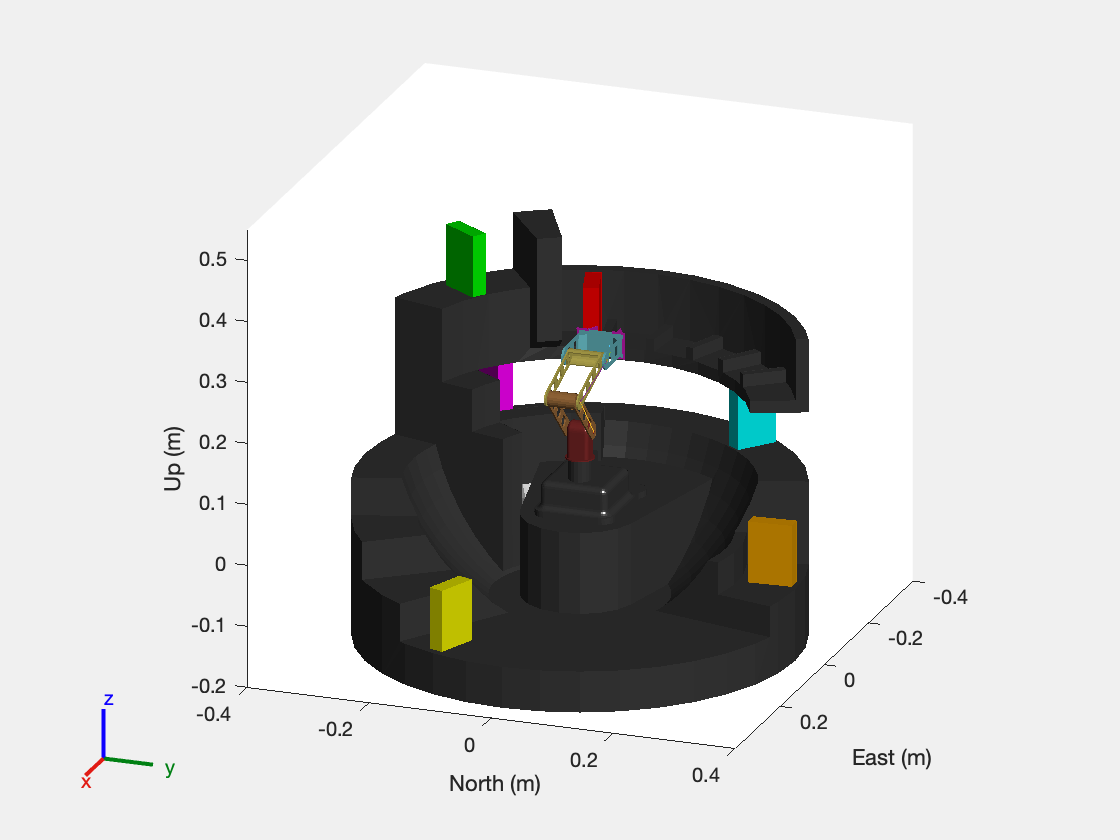



% Move to midpoint
animateRobotTrajectory(scenario, Robot, ax, secondPoint, mid_angles(2, :), numSteps, 1, 1);

### 5.2 - Book 2

%%%% Book 2 pick up and place down
%%%% Set loop number to 2
k = 2

k = 2


numPoints = size(eval(['final_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['final_angles_' num2str(k)]);  % final_angles_1, final_angles_2, ..., final_angles_6

%%% Move from the last point to the first position
animateRobotTrajectory(scenario, Robot, ax, mid_angles(2, :), current_angles(1, :), numSteps, 1, 1);

%% Loop through the 10 points mid-points (10 points)
for i = 1 : numPoints-1

    %% Set the points for the current row and the row below
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);

    %% Move between the two points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 1, 1);
end

% Close the end effector
animateRobotTrajectory(scenario, Robot, ax, secondPoint, secondPoint, numSteps, 1, 0);

%% Attach the book
attach(Robot, books{k}.name, "End_Effector_1", ...
    'ChildToParentTransform', customTransform);

% Record the current position for referncing
currentPoint = secondPoint;

%% Loop through and rotate the base ONLY
%% This is to move around the barrier

for i = 1:20
    nextPoint = currentPoint;
    nextPoint(1) = nextPoint(1) + 2;
    animateRobotTrajectory(scenario, Robot, ax, currentPoint, nextPoint, numSteps_mid, 0, 0);
    currentPoint = nextPoint;
end

%% Loop through the 10 points in reverse, bring the robot back
for i = numPoints-1 : -1 : 1

    %% Set the points for the current row and the row above
    firstPoint = purp_mid_bring_back(i+1, :);
    secondPoint = purp_mid_bring_back(i, :);

    %% Move between the two points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 0, 0);
end

% Record the current position
currentPoint = secondPoint;

% Set new angles as the shelf angles
numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]); 

% Move through midpoints to first shelf angle
animateRobotTrajectory(scenario, Robot, ax, currentPoint, mid_angles(3, :),  numSteps, 0, 0);
animateRobotTrajectory(scenario, Robot, ax, mid_angles(3, :), mid_angles(4, :),  numSteps, 0, 0);
animateRobotTrajectory(scenario, Robot, ax, mid_angles(4, :), current_angles(1, :),  numSteps, 0, 0);

%Move between shelf points slowly
for i = 1:numPoints - 1

    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);

    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 0, 0);
end

% Detatch the book
detach(Robot);

% Open the end effector
animateRobotTrajectory(scenario, Robot, ax, secondPoint, secondPoint, numSteps, 0, 1);

%Move slowly backwards
for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 1, 1);
end

### 5.3 - Book 3

%%%% Book 3 pick up and place down
%%%% Set loop number to 3
k = 3

numPoints = size(eval(['final_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['final_angles_' num2str(k)]);  % final_angles_1, final_angles_2, ..., final_angles_6

%%% Move from the first point, to a mid point and then the book position
animateRobotTrajectory(scenario, Robot, ax, secondPoint, between_point_angle(2, :), numSteps, 1, 1);
animateRobotTrajectory(scenario, Robot, ax, between_point_angle(2, :), current_angles(1, :),  numSteps, 1, 1);

% Open the end effector
animateRobotTrajectory(scenario, Robot, ax, current_angles(1, :), current_angles(1, :),  numSteps, 1, 0);

% Record the current position
currentPoint = current_angles(1, :);

% Set angles to red book reorientation angles
numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]);

%% Attach the book
attach(Robot, books{k}.name, "End_Effector_1", ...
    'ChildToParentTransform', green_book_trans);

%% Move back to the previous position and then the red book position for reorientatino
animateRobotTrajectory(scenario, Robot, ax, currentPoint, between_point_angle(2, :),  numSteps, 0, 0);
animateRobotTrajectory(scenario, Robot, ax, between_point_angle(2, :), red_pos_green,  numSteps*2, 0, 0);

% Detatch the book
detach(Robot);

% Open end effector
animateRobotTrajectory(scenario, Robot, ax, red_pos_green, red_pos_green,  numSteps, 0, 1);

% Reorientate the arm straight
animateRobotTrajectory(scenario, Robot, ax, red_pos_green, final_angles_1(10, :),  numSteps, 1, 1);

% Close end effector
animateRobotTrajectory(scenario, Robot, ax, final_angles_1(10, :), final_angles_1(10, :),  numSteps, 1, 0);

%% Attach the book
attach(Robot, books{k}.name, "End_Effector_1", ...
    'ChildToParentTransform', customTransform);

% Set the next angles to the shelf angles
numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]);

% Move to a mid-point and then the first shelf angles
animateRobotTrajectory(scenario, Robot, ax, final_angles_1(10, :), mid_point,  numSteps*2, 0, 0);
animateRobotTrajectory(scenario, Robot, ax, mid_point, current_angles(1, :),  numSteps, 0, 0);

% Loop through points to slowly put book down
for i = 1:numPoints - 1
    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);

    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 0, 0);
end

% Detach Book
detach(Robot);

% Open end effector
animateRobotTrajectory(scenario, Robot, ax, secondPoint, secondPoint, numSteps, 0, 1);


% Slowly move back out
for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 1, 1);
end


### 5.3 - Book 4

%%%% Book 4 pick up and place down
%%%% Set loop number to 4
k = 4

numPoints = size(eval(['final_angles_' num2str(k)]), 1);  
current_angles = eval(['final_angles_' num2str(k)]); 

%%% Move from the last config to a mid point and then the book angle
animateRobotTrajectory(scenario, Robot, ax, secondPoint, mid_point, numSteps, 1, 1);
animateRobotTrajectory(scenario, Robot, ax, mid_point, current_angles(1, :), numSteps, 1, 1);

% Set the current point
currentPoint = current_angles(1, :);

%Close the end effector
animateRobotTrajectory(scenario, Robot, ax, current_angles(1, :), current_angles(1, :), numSteps, 1, 0);

%% Attach the book
attach(Robot, books{k}.name, "End_Effector_1", ...
    'ChildToParentTransform', orange_book_trans);

% Move to a mid point and then the red book reorientation angles
animateRobotTrajectory(scenario, Robot, ax, currentPoint, between_point_angle(1, :),  numSteps, 0, 0);
animateRobotTrajectory(scenario, Robot, ax, between_point_angle(1, :), red_pos_orange,  numSteps, 0, 0);

% Detatch the robot
detach(Robot);

% Open end effector:
animateRobotTrajectory(scenario, Robot, ax, red_pos_orange, red_pos_orange,  numSteps, 0, 1);


% Move the robot arm straight
animateRobotTrajectory(scenario, Robot, ax, red_pos_orange, final_angles_1(10, :),  numSteps, 1, 1);

% Close end effector
animateRobotTrajectory(scenario, Robot, ax, final_angles_1(10, :), final_angles_1(10, :),  numSteps, 1, 0);

%% Attach the book
attach(Robot, books{k}.name, "End_Effector_1", ...
    'ChildToParentTransform', customTransform);

% Set the next co-ordinates as the shelf cords
numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]);

% Move to a mid point and then the first shelf cord 

animateRobotTrajectory(scenario, Robot, ax, final_angles_1(10, :), mid_point,  numSteps*2, 0, 0);
animateRobotTrajectory(scenario, Robot, ax, mid_point, current_angles(1, :),  numSteps, 0, 0);

% Move through shelf cords and slowly put book down
for i = 1:numPoints - 1

    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 0, 0);
end

% Detatch Book
detach(Robot);

% Open end effector
animateRobotTrajectory(scenario, Robot, ax, secondPoint, secondPoint, numSteps, 0, 1);

% Slowly move back out
for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 1, 1);
end


### 5.3 - Book 5

%%%% Book 5 pick up and place down
%%%% Set loop number to 5
k = 5

numPoints = size(eval(['final_angles_' num2str(k)]), 1); 
current_angles = eval(['final_angles_' num2str(k)]); 

%%% Move from the position to book angle position
animateRobotTrajectory(scenario, Robot, ax, secondPoint, current_angles(1, :), numSteps*2, 1, 1);

% Set current position
currentPoint = current_angles(1, :);

% Close end effector
%%% Move from the position to book angle position
animateRobotTrajectory(scenario, Robot, ax, current_angles(1, :), current_angles(1, :), numSteps, 1, 0);

%% Attach the book
attach(Robot, books{k}.name, "End_Effector_1", ...
    'ChildToParentTransform', yellow_book_trans);

% Move to a mid point and then the red book reorientation position
animateRobotTrajectory(scenario, Robot, ax, currentPoint, between_point_angle(3, :),  numSteps, 0, 0);
animateRobotTrajectory(scenario, Robot, ax, between_point_angle(3, :), red_pos_yellow,  numSteps, 0, 0);

% Detatch book
detach(Robot);

% Open end effector
animateRobotTrajectory(scenario, Robot, ax, red_pos_yellow, red_pos_yellow,  numSteps, 0, 1);

% Reorientate the arm
animateRobotTrajectory(scenario, Robot, ax, red_pos_yellow, final_angles_1(10, :),  numSteps, 1, 1);

% Close end effector
animateRobotTrajectory(scenario, Robot, ax, final_angles_1(10, :), final_angles_1(10, :),  numSteps, 1, 0);

%% Attach the book
attach(Robot, books{k}.name, "End_Effector_1", ...
    'ChildToParentTransform', customTransform);

% Set shelf cords as current cords
numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]);

% Move to a mid point and then a first shelf cord
animateRobotTrajectory(scenario, Robot, ax, final_angles_1(10, :), mid_point,  numSteps*2, 0, 0);
animateRobotTrajectory(scenario, Robot, ax, mid_point, current_angles(1, :),  numSteps, 0, 0);

% Slowly move to the put the book down
for i = 1:numPoints - 1

    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);

    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 0, 0);
end

% Drop book
detach(Robot);

% Open end effector
animateRobotTrajectory(scenario, Robot, ax, secondPoint, secondPoint, numSteps, 0, 1);

% Slowly move back out
for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 1, 1);
end

% Record last point
last_point = current_angles(1, :);

### 5.3 - Book 6

%%%% Book 6 pick up and place down
%%%% Set loop number to 6
k = 6

numPoints = size(eval(['final_angles_' num2str(k)]), 1);
current_angles = eval(['final_angles_' num2str(k)]);

%%% Move from the first position to book position
animateRobotTrajectory(scenario, Robot, ax, last_point, current_angles(1, :), numSteps, 1, 1);

%% Loop through the 10 points mid-points to slowly pick up book
for i = 1 : numPoints-1

    %% Set the points for the current row and the row below
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);

    %% Move between the two points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 1, 1);
end

% Close end effector
animateRobotTrajectory(scenario, Robot, ax, secondPoint, secondPoint, numSteps, 1, 0);

%% Attach the book
attach(Robot, books{k}.name, "End_Effector_1", ...
    'ChildToParentTransform', customTransform);

% Set next cords as the shelf cords
numPoints = size(eval(['shelf_angles_' num2str(k)]), 1);  % Number of points (rows)
current_angles = eval(['shelf_angles_' num2str(k)]); 

% Move between two mid points and then to the first shelf cord
animateRobotTrajectory(scenario, Robot, ax, secondPoint, mid_angles(3, :),  numSteps, 0, 0);
animateRobotTrajectory(scenario, Robot, ax, mid_angles(3, :), mid_angles(4, :),  numSteps, 0, 0);
animateRobotTrajectory(scenario, Robot, ax, mid_angles(4, :), current_angles(1, :),  numSteps, 0, 0);

% Slowly put the book down
for i = 1:numPoints - 1

    % Extract the current point and the next point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i+1, :);

    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 0, 0);
end

% Drop book
detach(Robot);

% Open end effector
animateRobotTrajectory(scenario, Robot, ax, secondPoint, secondPoint, numSteps, 0, 1);

% Slowly move back out
for i = numPoints:-1:2
    % Extract the current point and the previous point
    firstPoint = current_angles(i, :);
    secondPoint = current_angles(i-1, :);

    % Call the animateRobotTrajectory function for each pair of consecutive points
    animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid, 1, 1);
end

% Return to home config
animateRobotTrajectory(scenario, Robot, ax, secondPoint, homeconfig, numSteps, 1, 1);

## A) Functions:

### A.1 Radius and Height

% This function finds the radius and height of the book from the centre point
function results = calculateResults(bookPositions, L1)
    
    % Get the number of rows
    numRows = size(bookPositions, 1);

    % Make a matrix of zeros
    % It will have the same number of rows as bookPositions, but only 2 columns
    results = zeros(numRows, 2);

    % Loop through each row of the bookPositions matrix
    for i = 1:numRows
        % Extract the first element (a) and second element (b) from the current row
        a = bookPositions(i, 1);
        b = bookPositions(i, 2);

        % Calculate the radius r = sqrt(a^2 + b^2)
        radius = sqrt(a^2 + b^2);

        % Assign the calculated radius to the first column of the results matrix
        results(i, 1) = radius;

        % Assign the third element from the original row to the second column
        results(i, 2) = bookPositions(i, 3);

        % Minus the centre position cords 
        results(i, 2) = results(i, 2) - L1;
    end

    % Display the final results matrix
    disp('Results Matrix (Radius, Original Z):');
    disp(results);

end

### A.2 Anmiate Robot Functon

% This function moves the robot from one position to another
function animateRobotTrajectory(scenario, Robot, ax, q_start_deg, q_end_deg, numSteps, start_state, end_state)
    
    if nargin < 9
        hideFrames = true;
    end

    % Ensure input vectors are row vectors
    q_start_deg = reshape(q_start_deg, 1, []);
    q_end_deg = reshape(q_end_deg, 1, []);

    % Pad to 6 joints if needed (e.g. robot expects 6 DOF input)
    if length(q_start_deg) < 6
        q_start_deg = [q_start_deg, zeros(1, 6 - length(q_start_deg))];
    end
    if length(q_end_deg) < 6
        q_end_deg = [q_end_deg, zeros(1, 6 - length(q_end_deg))];
    end

    if start_state == 1
        q_start_deg(1, 5) = -0.20;
        q_start_deg(1, 6) = 0.20;

    else
        q_start_deg(1, 5) = 0.1;
        q_start_deg(1, 6) = -0.1;
    end


    if end_state == 1
        q_end_deg(1, 5) = -0.20;
        q_end_deg(1, 6) = 0.20;
    else
        q_end_deg(1, 5) = 0.1;
        q_end_deg(1, 6) = -0.1;
    end


    % Convert degrees to radians
    q_start = deg2rad(q_start_deg);
    q_end = deg2rad(q_end_deg);

    % Wrap angle differences to ensure shortest path
    delta = wrapToPi(q_end - q_start);  % ensures minimal rotation

    % Time parameter [0, 1]
    % This makes the robot intially slower, then faster and then slow again
    t = linspace(0, 1, numSteps);
    s = 0.5 * (1 - cos(pi * t));  % Cosine ease-in-out

    % Interpolate trajectory 
    q_traj = q_start + s' .* delta;

    % ---- Animate ----
    for k = 1:numSteps

        move(Robot, "joint", q_traj(k, :));

        cla(ax);
        show3D(scenario, Collisions="off");
        light(ax, 'Position', [1 1 1], 'Style', 'infinite');
        view(ax, 110, 20)
        axis(ax, 'equal'); 
        xlim(ax, [-0.4 0.4] ); 
        ylim(ax, [-0.4 0.4] ); 
        zlim(ax, [-0.2 0.55])
       
        % Hide the frames of the robot
        if hideFrames
            gfx_Frames = findall(ax, 'FaceColor', 'flat');
            set(gfx_Frames, 'FaceAlpha', 0);
            gfx_Base_Frame = findall(ax, 'DisplayName', 'Base_Link');
            set(gfx_Base_Frame, 'FaceAlpha', 0);
        end

        drawnow;
        pause(0.01);

    end

end

### A.3 Find Theta 1

% This finds theta_1 (the base rotation) for each position using trig
function theta1_values = calculateTheta1(bookPositions, centre)
    numRows = size(bookPositions, 1);
    theta1_values = zeros(numRows, 1);

    for i = 1:numRows
        P = bookPositions(i, :);

        % Minus the values of centre to just get the length
        P(1) = -(P(1) - centre(1));
        P(2) = P(2) - centre(2);

        % Inverse Trig to find values
        theta1 = atan2(P(2), P(1));
        theta1_values(i) = rad2deg(theta1);
    end
end

### A.4 Find Theta 2 (Main Calculation)

function theta_values = calculateTheta234(results, L2, L3, L4, theta4_offset)
    numRows = size(results, 1);
    theta_values = zeros(numRows, 3);

    for i = 1:numRows
        r_target = results(i, 1);
        z_target = results(i, 2);
        z_target = -z_target;  % Flip the z-coordinate based on the setup

        % Calculate the angle to the target in the plane (XY)
        angle_to_target = atan2(z_target, r_target);

        % Calculate the wrist position
        wrist_r = r_target - L4 * cos(angle_to_target);
        wrist_z = z_target - L4 * sin(angle_to_target);

        % Calculate the distance from the wrist to the base
        d = sqrt(wrist_r^2 + wrist_z^2);

        % Solve for theta3 using the law of cosines
        cos_theta3 = (d^2 - L2^2 - L3^2) / (2 * L2 * L3);
        cos_theta3 = min(max(cos_theta3, -1), 1);
        theta3 = acos(cos_theta3);

        % Solve for theta2
        alpha = atan2(wrist_z, wrist_r);
        cos_beta = (L2^2 + d^2 - L3^2) / (2 * L2 * d);
        cos_beta = min(max(cos_beta, -1), 1);
        beta = acos(cos_beta);
        theta2 = alpha - beta;

        % Calculate theta4 based on previous angles to keep the last limb horizontal
        % Theta4 is adjusted relative to theta2 and theta3 to ensure it remains horizontal with the ground

        % Calculate the orientation of the third limb (theta2 + theta3 combined)
        orientation_of_third_limb = theta2 + theta3;
        
        % Ensure the last joint (theta4) makes the final limb horizontal relative to the ground
        % This is done by theta4_offset = 0
        % For picking the book up at an angle, theta4_offset is set to readjust
        theta4 = orientation_of_third_limb + theta4_offset;

        % Store the calculated angles in the output array, converting to degrees
        theta_values(i, 1) = rad2deg(theta2);  % Theta 2
        theta_values(i, 2) = rad2deg(theta3);  % Theta 3
        theta_values(i, 3) = rad2deg(theta4);  % Theta 4

    end

end

### A.5 Find Theta 2 (Books 3, 4 & 5)

% Function to calculate Theta 2, 3, and 4 for books 3,4,5
% This follow a simillar method as outlined above, but makes the robot
% straight instead
function theta_values = calculateTheta234_bend(results, L2, L3, L4)
    numRows = size(results, 1);
    theta_values = zeros(numRows, 3);

    for i = 1:numRows
        r_target = results(i, 1);
        z_target = results(i, 2);
        z_target = -z_target;

        angle_to_target = atan2(z_target, r_target);

        wrist_r = r_target - L4 * cos(angle_to_target);
        wrist_z = z_target - L4 * sin(angle_to_target);

        d = sqrt(wrist_r^2 + wrist_z^2);

        cos_theta3 = (d^2 - L2^2 - L3^2) / (2 * L2 * L3);
        cos_theta3 = min(max(cos_theta3, -1), 1);
        theta3 = acos(cos_theta3);

        alpha = atan2(wrist_z, wrist_r);
        cos_beta = (L2^2 + d^2 - L3^2) / (2 * L2 * d);
        cos_beta = min(max(cos_beta, -1), 1);
        beta = acos(cos_beta);
        theta2 = alpha - beta;

        theta4 = angle_to_target - theta2 - theta3;

        theta_values(i, 1) = rad2deg(theta2);
        theta_values(i, 2) = rad2deg(theta3);
        theta_values(i, 3) = rad2deg(theta4);

    end

end

## Submission Instructions and Deadline

**Deadline: **Week 23 - Thursday @15:00 - 01/05/2025

**You will submit:**

- The complete code of your solution as a MATLAB Live Script, please also include outputs (e.g. do not clear the outputs after processing)

- Please, export your MATLAB Live Script as a PDF with the same file name. Only include outputs that are necessary to explain your process or those that show important milestones in the coursework (basically, please don't output everything making the document huge)

- Please refer to the hadnout for further instructions.

**MECH3465 CW2 2025 **| Written by ***Louie Burns & Dan Nehushtan***

*Email: ****mn22lb@leeds.ac.uk & mn22dn@leeds.ac.uk***